# Global Irminger Sea: Apex Surface Mooring 

Kristen Fogaren 8/3/2023

#### Overview

This notebook goes through calibrating OOI GI Apex Surface Mooring dissolved oxygen assets (NSIF, Surface Buoy) for Deployments 5 through 8. 

## Assemble data  

### [Quick look at oxygen data](https://dataexplorer.oceanobservatories.org/?ls=Ug47DZqe#data/5) available on Data Explorer and saved as Data View 

### Look at HITL and QARTOD annotations associated with oxygen and ancillary (temp, sal, pressure) parameters

- HITL annotations and QARTOD results for [oxygen data](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#metadata/104058/station/95/sensor/annotations?start=2015-08-15T19:30:00Z&end=2023-08-02T02:18:00Z&leg_clim_max=false&leg_clim_min=false) 

- HITL annotations and QARTOD results for [CTD data](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#metadata/104055/station/7/sensor/annotations?start=2018-05-23T01:09:41Z&end=2023-07-07T16:17:00Z&bin=days&leg_clim_max=false&leg_clim_min=false&leg_minmax=false&leg_clim_upper_env=false&leg_clim_lower_env=false&leg_clim_mean=false)

RESULTS: 

- The use of UV lamps has been implemented for bio-fouling mitigation on this instrument as of the start date/time of this annotation. (April 2018)

- Note, no QARTOD tests are implemented at this time for oxygen data streams

- Several annotations about power outages and resulting data gaps 

- CTD Deployment 5: Instrument unable to succesfully power on and sample since 2/7/2019. Any data after this date are suspect. Instrument may be collecting data internally on battery power, but is unlikely.

- DO Deployment 7: Upon recovery it was noted that the power pin for the UV light cable was corroded. The light likely stopped being powered at some point during the deployment. This instrument did not have noticeable biofouling.

- CTD and DO Deployment 0008 - No Data Available

### Download discrete bottle summaries from Alfresco server

- [https://alfresco.oceanobservatories.org/](https://alfresco.oceanobservatories.org/)

- Find turn-around cruises that bookend deployments of interest (deployments 5 through 9)

- CTD casts and discrete bottle data has been processed and collated from turn-around cruises  

### Summary of CTD cast and bottle data from turn-around cruises 

**Year 5 AR30-03: **

- CTD data collected at Stations 7-12 experienced issues associated with biofouling.

- Portions of Casts from stations 7-8 and 11-12 have been flagged as questionable as they exhibit  behavior indicative of biofouling.

**Year 6 AR35-05**: 

- Oxygen profiles were collected using an Aanderaa optode because of issues with the SBE43-DO sensor. 

- All data has been flagged as questionable because of the inability for Aanderaa optodes to resolve strong oxygen gradients at CTD rosette profiling speeds.

- A broken pylon resulted in no discrete water samples for calibration prior to Station 11.

**Year 7 AR46:** 

- COVID-affected cruise. No discrete oxygen measurements for AR46. 

- Oxygen profiles from AR46 were collected using an Aanderaa optode that was calibrated during the previous cruise (AR45) using water samples that were stored and not measured onboard.

- All data has been flagged as questionable because of these issues and also because of the inability for Aanderaa optodes to resolve strong oxygen gradients at CTD rosette profiling speeds.

**Year 8 AR60-01:** 

- Examination of Winklers and CTD-measured oxygen values revealed issues with Winklers collected from casts 5 -12. 

- Residuals from casts 5-12 were relatively large and more than half of the Winklers were flagged as outliers. 

- Also, oxygen data collected on the upcast from Cast 10 between ~750 - 920 db is consistent with pump clogging and has been flagged as questionable.

**Year 9 AR69-01:** 

- No known issues. 

### Download NSIF Data

- This code uses local function to read in netCDFs directly from the THREDDS server and into data structures

- Reads in data from oxygen sensor and co-located CTD  

- Uses recovered data stream (telemetered data does not add any temporal coverage). 

% 
% %Pull DO data 
% nsif_rec = 'GI01SUMO-RID16-06-DOSTAD000-recovered_host-dosta_abcdjm_dcl_instrument_recovered'; % NSIF Recovered
% % nsif_tel = 'GI01SUMO-RID16-06-DOSTAD000-telemetered-dosta_abcdjm_dcl_instrument'; % NSIF Telemetered 
% 
% % Pull data for recovered and telemetered streams for NSIF 
% nsif_DOrec5 = pull_DO_Data_from_THREDDS('deployment0005',nsif_rec); 
% % nsif_DOtel5 = pull_DO_Data_from_THREDDS('deployment0005',nsif_tel); 
% 
% nsif_DOrec6 = pull_DO_Data_from_THREDDS('deployment0006',nsif_rec);
% % nsif_DOtel6 = pull_DO_Data_from_THREDDS('deployment0006',nsif_tel); 
% % 
% nsif_DOrec7 = pull_DO_Data_from_THREDDS('deployment0007',nsif_rec);
% % nsif_DOtel7 = pull_DO_Data_from_THREDDS('deployment0007',nsif_tel); 
% 
% nsif_DOrec8 = pull_DO_Data_from_THREDDS('deployment0008',nsif_rec);
% % nsif_DOtel8 = pull_DO_Data_from_THREDDS('deployment0008',nsif_tel);
% 
% %% Calculate other parameters of interest from sal and temperature 
% nsif_DOrec5 = GSW_variables(nsif_DOrec5);
% nsif_DOrec6 = GSW_variables(nsif_DOrec6);
% nsif_DOrec7 = GSW_variables(nsif_DOrec7);
% nsif_DOrec8 = GSW_variables(nsif_DOrec8); 

%% This output has been saved as NSIF_thredds.mat in G:\Shared drives\NSF_Irminger\OOI_DO_fixed_depth\Data\nsif

## Plot NSIF Data 

% 
% % Plot to see coverage of different streams 
% % Plot CTD/Anderra deployments by color 
% run('GeneralSettings.m')
% cd('G:\Shared drives\NSF_Irminger\OOI_DO_fixed_depth\Data\nsif')
% load NSIF_thredds.mat 
% 
% f0 = figure;
% f0.Position = [200 200 700 500];
% subplot(3,1,1)
% plot(nsif_DOrec5.DOdt,nsif_DOrec5.sea_water_temperature,'.')
% hold on
% plot(nsif_DOrec6.DOdt,nsif_DOrec6.sea_water_temperature,'.')
% plot(nsif_DOrec7.DOdt,nsif_DOrec7.sea_water_temperature,'.')
% plot(nsif_DOrec8.DOdt,nsif_DOrec8.sea_water_temperature,'.')
% plot(nsif_DOrec5.DOdt,nsif_DOrec5.optode_temperature,'k')
% plot(nsif_DOrec6.DOdt,nsif_DOrec6.optode_temperature,'k')
% plot(nsif_DOrec7.DOdt,nsif_DOrec7.optode_temperature,'k')
% plot(nsif_DOrec8.DOdt,nsif_DOrec8.optode_temperature,'k')
% ylabel('temp. (\circC)')
% grid on
% 
% subplot(3,1,2)
% plot(nsif_DOrec5.DOdt,nsif_DOrec5.sea_water_practical_salinity,'.')
% hold on
% plot(nsif_DOrec6.DOdt,nsif_DOrec6.sea_water_practical_salinity,'.')
% plot(nsif_DOrec7.DOdt,nsif_DOrec7.sea_water_practical_salinity,'.')
% plot(nsif_DOrec8.DOdt,nsif_DOrec8.sea_water_practical_salinity,'.')
% ylabel('Salinity')
% grid on
% 
% subplot(3,1,3)
% plot(nsif_DOrec5.DOdt,nsif_DOrec5.dissolved_oxygen,'.')
% hold on
% plot(nsif_DOrec6.DOdt,nsif_DOrec6.dissolved_oxygen,'.')
% plot(nsif_DOrec7.DOdt,nsif_DOrec7.dissolved_oxygen,'.')
% plot(nsif_DOrec8.DOdt,nsif_DOrec8.dissolved_oxygen,'.')
% ylabel('L2-DO (\mumol kg^-^1)')
% grid on
% sgtitle('Irminger Array: NSIF')

- Top panel shows CTD temperature by deployment in colors. Black data shows AA optode temperature

- Looks like missing CTD temp and sal data from Deployment 5 has been filled with dummy data in order to process oxygen data 

- L2- DO data is OOI highest level user-available product 

- Need to reprocess oxygen data using optode temperature and dummy salinity data 

- *** This is not anywhere in the annotations?

### Calculate and plot median of 3-min DO burst sampling

- Aanderra sensor burst samples at 0.5 Hz for 3 minutes every 15 minutes

- The science idea behind 3 minute burst is it gives you enough data to average over a series of wave cycles, minimizing the impact of surface waves on the measurement- Chris Wingard, personal communication  

% % calculates median for each burst and retimes timetable  
% 
% nsif_DO5 = burst_THREDDS_files_to_timetable(nsif_DOrec5,minutes(15));
% nsif_DO6 = burst_THREDDS_files_to_timetable(nsif_DOrec6,minutes(15));
% nsif_DO7 = burst_THREDDS_files_to_timetable(nsif_DOrec7,minutes(15)); % This deployment takes a long time
% nsif_DO8 = burst_THREDDS_files_to_timetable(nsif_DOrec8,minutes(15));

%% above output has been saved as NSIF_timetable_pre.mat in G:\Shared drives\NSF_Irminger\OOI_DO_fixed_depth\Data\nsif

% Plot burst medians
run('GeneralSettings.m')
cd('G:\Shared drives\NSF_Irminger\OOI_DO_fixed_depth\Data\mixed_layer')
load NSIF_timetable_pre.mat
f0 = figure;
f0.Position = [200 200 700 500];
ax1 = subplot(3,1,1);
plot(nsif_DO5.DOdt,nsif_DO5.t,'.')
hold on
plot(nsif_DO6.DOdt,nsif_DO6.t,'.')
plot(nsif_DO7.DOdt,nsif_DO7.t,'.')
plot(nsif_DO8.DOdt,nsif_DO8.t,'.')
plot(nsif_DO5.DOdt,nsif_DO5.optode_temperature,'k')
plot(nsif_DO6.DOdt,nsif_DO6.optode_temperature,'k')
plot(nsif_DO7.DOdt,nsif_DO7.optode_temperature,'k')
plot(nsif_DO8.DOdt,nsif_DO8.optode_temperature,'k')
ylabel('Temp (\circC)')
grid on

ax2 = subplot(3,1,2);
plot(nsif_DO5.DOdt,nsif_DO5.SP,'.')
hold on
plot(nsif_DO6.DOdt,nsif_DO6.SP,'.')
plot(nsif_DO7.DOdt,nsif_DO7.SP,'.')
plot(nsif_DO8.DOdt,nsif_DO8.SP,'.')
ylabel('Salinity')
grid on

ax3 = subplot(3,1,3);
plot(nsif_DO5.DOdt,nsif_DO5.dissolved_oxygen,'.')
hold on
plot(nsif_DO6.DOdt,nsif_DO6.dissolved_oxygen,'.')
plot(nsif_DO7.DOdt,nsif_DO7.dissolved_oxygen,'.')
plot(nsif_DO8.DOdt,nsif_DO8.dissolved_oxygen,'.')
ylabel('L2-DO (\mumol kg^-^1)')
grid on
linkaxes([ax3 ax2 ax1],'x')
sgtitle('Uncalibrated NSIF Data')


### Download SUMO Data

- This code uses local function to read in netCDFs directly from the THREDDS server and into data structures

- Reads in data from oxygen sensor and co-located CTD  

- Uses both recovered and telemetered data streams 

- Data recorded every 2 sec and then averaged into 15 min blocks 

- Data pull from THREDDS and retiming takes ~ 4 hours to run 

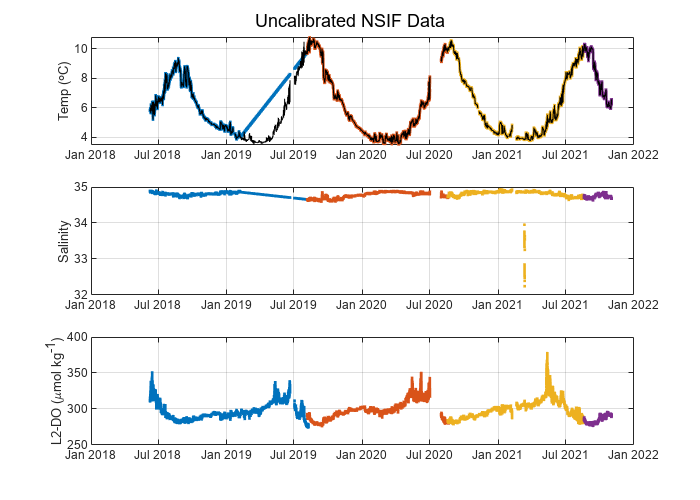

% % SUMO already run and saved 
% tic
% buoy_rec = 'GI01SUMO-SBD11-04-DOSTAD000-recovered_host-dosta_abcdjm_dcl_instrument_recovered'; % Surface Buoy Recovered
% buoy_tel = 'GI01SUMO-SBD11-04-DOSTAD000-telemetered-dosta_abcdjm_dcl_instrument'; % Surface Buoy Telemetered 
% 
% % Pull data for recovered and telemetered streams for surface buoy
% buoy_DOrec5 = pull_DO_Data_from_THREDDS('deployment0005',buoy_rec);
% buoy_DOtel5 = pull_DO_Data_from_THREDDS('deployment0005',buoy_tel); 


% buoy_DOrec6 = pull_DO_Data_from_THREDDS('deployment0006',buoy_rec);
% buoy_DOtel6 = pull_DO_Data_from_THREDDS('deployment0006',buoy_tel); 

% buoy_DOrec7 = pull_DO_Data_from_THREDDS('deployment0007',buoy_rec);
% buoy_DOtel7 = pull_DO_Data_from_THREDDS('deployment0007',buoy_tel); 

% buoy_DOrec8 = pull_DO_Data_from_THREDDS('deployment0008',buoy_rec);
% buoy_DOtel8 = pull_DO_Data_from_THREDDS('deployment0008',buoy_tel); 
% 
% %% Calculate other parameters of interest from sal and temperature 
% buoy_DOrec5 = GSW_variables(buoy_DOrec5);
% buoy_DOrec6 = GSW_variables(buoy_DOrec6);
% buoy_DOrec7 = GSW_variables(buoy_DOrec7);
% buoy_DOrec8 = GSW_variables(buoy_DOrec8); 
% 
% %% Calculate other parameters of interest from sal and temperature 
% buoy_DOtel5 = GSW_variables(buoy_DOtel5);
% buoy_DOtel6 = GSW_variables(buoy_DOtel6);
% buoy_DOtel7 = GSW_variables(buoy_DOtel7);
% buoy_DOtel8 = GSW_variables(buoy_DOtel8); 

% 
% buoy_DO5 = combine_THREDDS_files_to_timetable([buoy_DOrec5; buoy_DOtel5],minutes(15));
% buoy_DO6 = combine_THREDDS_files_to_timetable([buoy_DOrec6; buoy_DOtel6],minutes(15));
% buoy_DO7 = combine_THREDDS_files_to_timetable([buoy_DOrec7; buoy_DOtel7],minutes(15));
% buoy_DO8 = combine_THREDDS_files_to_timetable([buoy_DOrec8; buoy_DOtel8],minutes(15));
% toc
% % Takes ~ 4 hours to run 
% % saved as buoy_timetable_pre.mat in G:\Shared drives\NSF_Irminger\OOI_DO_fixed_depth\Data\buoy

## Figures comparing SUMO and NSIF values before calibration

cd('G:\Shared drives\NSF_Irminger\OOI_DO_fixed_depth\Data\mixed_layer')
load buoy_timetable_pre.mat
f0 = figure;
f0.Position = [200 200 700 500];
ax1 = subplot(3,1,1);
plot(nsif_DO5.DOdt,nsif_DO5.t,'.')
hold on
plot(nsif_DO6.DOdt,nsif_DO6.t,'.')
plot(nsif_DO7.DOdt,nsif_DO7.t,'.')
plot(nsif_DO8.DOdt,nsif_DO8.t,'.')
plot(buoy_DO5.DOdt,buoy_DO5.t,'k')
plot(buoy_DO6.DOdt,buoy_DO6.t,'k')
plot(buoy_DO7.DOdt,buoy_DO7.t,'k')
plot(buoy_DO8.DOdt,buoy_DO8.t,'k')
ylabel('Temp (\circC)')
grid on

ax2 = subplot(3,1,2);
plot(nsif_DO5.DOdt,nsif_DO5.SP,'.')
hold on
plot(nsif_DO6.DOdt,nsif_DO6.SP,'.')
plot(nsif_DO7.DOdt,nsif_DO7.SP,'.')
plot(nsif_DO8.DOdt,nsif_DO8.SP,'.')
plot(buoy_DO5.DOdt,buoy_DO5.SP,'k')
plot(buoy_DO6.DOdt,buoy_DO6.SP,'k')
plot(buoy_DO7.DOdt,buoy_DO7.SP,'k')
plot(buoy_DO8.DOdt,buoy_DO8.SP,'k')
ylabel('Salinity')
grid on

ax3 = subplot(3,1,3);
plot(nsif_DO5.DOdt,nsif_DO5.dissolved_oxygen,'.')
hold on
plot(nsif_DO6.DOdt,nsif_DO6.dissolved_oxygen,'.')
plot(nsif_DO7.DOdt,nsif_DO7.dissolved_oxygen,'.')
plot(nsif_DO8.DOdt,nsif_DO8.dissolved_oxygen,'.')
plot(buoy_DO5.DOdt,buoy_DO5.dissolved_oxygen,'k')
plot(buoy_DO6.DOdt,buoy_DO6.dissolved_oxygen,'k')
plot(buoy_DO7.DOdt,buoy_DO7.dissolved_oxygen,'k')
plot(buoy_DO8.DOdt,buoy_DO8.dissolved_oxygen,'k')
ylabel('L2-DO (\mumol kg^-^1)')
grid on
linkaxes([ax3 ax2 ax1],'x')
legend('Deploy 5','Deploy 6','Deploy 7','Deploy 8','BUOY','Orientation','horizontal','Location','southoutside')
sgtitle('Uncalibrated NSIF + SUMO Data')

## Deployment 5 Temperature and Salinity Correction for NSIF  

- After looking through [OOI processing code on github](https://github.com/oceanobservatories/ion-functions/blob/master/ion_functions/data/do2_functions.py) determined that variable 'estimated_oxygen_concentration' is the Level 1 data product before application of CTD temp/salinity/pressure correction and conversion from umol/L to umol/kg

- Used Hilary's aaoptode_salpresscorr.m and OOI code to replicate OOI do2_salinity_correction python function 

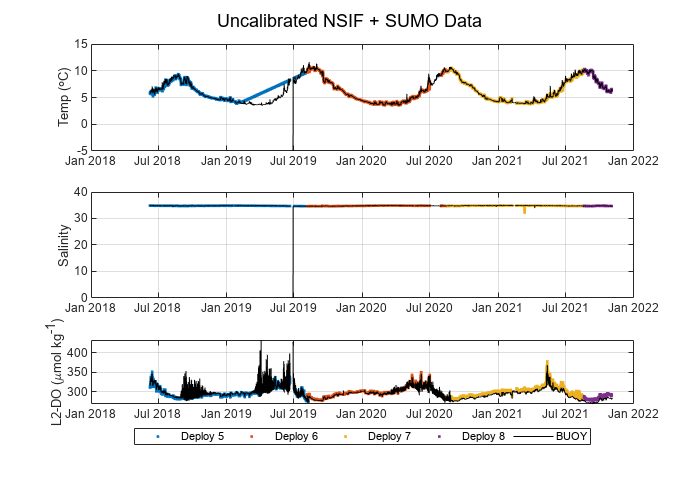

cd('G:\My Drive\Matlab_work\BC\Fogaren-OOI-Irminger\OOI_Fixed_Depth_Assets')
[OOI_DO_replicate] = do2_salinity_correction(nsif_DO5.estimated_oxygen_concentration, nsif_DO5.prs, nsif_DO5.t, nsif_DO5.SP, nsif_DO5.lat, nsif_DO5.lon, 0); 

badind = find(nsif_DO5.DOdt >= datetime(2019,02,07),1,'first');
nsif_DO5.sea_water_practical_salinity(badind:end) = buoy_DO5.sea_water_practical_salinity(badind:end); % replace dummy salinity values with buoy values
nsif_DO5.sea_water_temperature(badind:end) = nsif_DO5.optode_temperature(badind:end); % replace dummy temperature values with optode temperature values 
% Remove when buoy temp/sal = 0 
badind2 = find(nsif_DO5.t < 0);
nsif_DO5.sea_water_temperature(badind2) = NaN;
nsif_DO5.sea_water_practical_salinity(badind2) = NaN;

nsif_DO5.dissolved_oxygen(badind2) = NaN;

nsif_DO5 = GSW_variables(nsif_DO5); % recalculate GSW variables 

[DO_temp_corrected] = do2_salinity_correction(nsif_DO5.estimated_oxygen_concentration, nsif_DO5.prs, nsif_DO5.t, nsif_DO5.SP, nsif_DO5.lat, nsif_DO5.lon, 0); 

figure
plot(nsif_DO5.DOdt,nsif_DO5.dissolved_oxygen-OOI_DO_replicate)
ylabel('DO Difference (umol/kg)')
title('OOI L2 DO - My L1 to L2 Processing')
grid on

- Figure shows difference between Level 2 OOI DO product and DO result using do2_salinity_correction to convert L1 product to L2 product 

- Confirms that estimated_oxygen_concentration is L1 OOI product and my function is coded correctly

figure
plot(nsif_DO5.DOdt,nsif_DO5.dissolved_oxygen-DO_temp_corrected)
ylabel('DO Difference (\mumol/kg)')
title('OOI L2 DO (with dummy Temp/Sal) - Recalculated L2 DO with optode temp/SUMO sal')
grid on

- Difference between OOI L2 product with dummy temperature and salinity product when co-located CTD data is missing and recalculated L2 product using optode temperature and SUMO buoy CTD salinity product when co-located CTD data is missing

- Temperature difference of ~ 3 C results in ~1.7 umol/kg difference in recalculated Level 2 product 

- Recalculated Level 2 product replaces original OOI provided Level 2 product 

nsif_DO5.dissolved_oxygen = DO_temp_corrected; % update variable to include temperature correction using optode foil temperature 

## Closer look at DO comparison between SUMO/NSIF

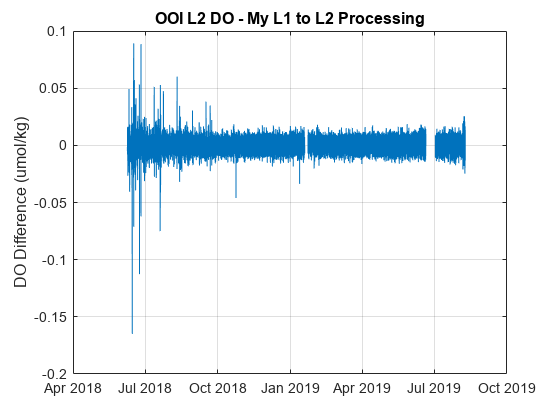

figure
subplot(4,1,1)
plot(nsif_DO5.DOdt,nsif_DO5.dissolved_oxygen,'.','Color',blue)
hold on
plot(buoy_DO5.DOdt,buoy_DO5.dissolved_oxygen,'k')

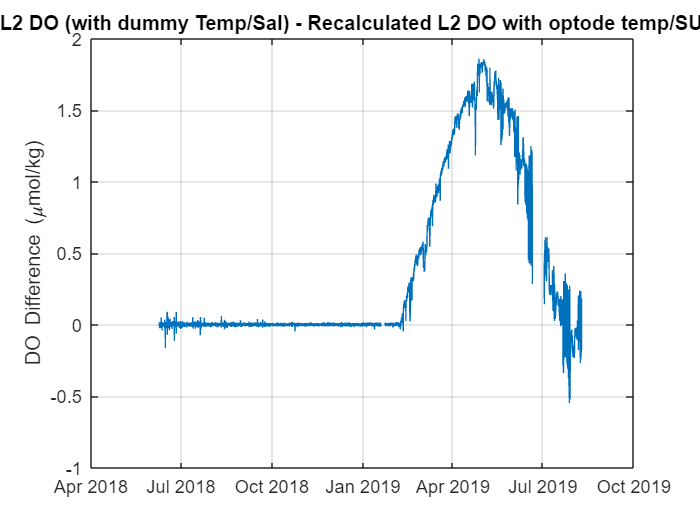

ylabel('L2 DO (umol/kg)')
xlim([datetime(2018,06,01) datetime(2019,11,01)])

subplot(4,1,2)
plot(nsif_DO6.DOdt,nsif_DO6.dissolved_oxygen,'.','Color',red)
hold on

plot(buoy_DO6.DOdt,buoy_DO6.dissolved_oxygen,'k')
ylabel('L2 DO (umol/kg)')
xlim([datetime(2019,06,01) datetime(2020,11,01)])

subplot(4,1,3)
plot(nsif_DO7.DOdt,nsif_DO7.dissolved_oxygen,'.','Color',yellow)
hold on
plot(buoy_DO7.DOdt,buoy_DO7.dissolved_oxygen,'k')
ylabel('L2 DO (umol/kg)')
xlim([datetime(2020,06,01) datetime(2021,11,01)])

subplot(4,1,4)
plot(nsif_DO8.DOdt,nsif_DO8.dissolved_oxygen,'.','Color',purple)
hold on
plot(buoy_DO8.DOdt,buoy_DO8.dissolved_oxygen,'k')
ylabel('L2 DO (umol/kg)')
xlim([datetime(2021,06,01) datetime(2022,11,01)])

## Deployment 5 DO Calibration 

%% Load in calibrated CTD profiles and bottle files 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Processed')
load Year5_Processed_KF.mat
AssetRadius = 10; % distance in km 


#### Calculate AA gain at beginning of deployment for NSIF and SUMO (buoy)

[nsif_yr5s, nsif_yr5s_tbl] = AAgain_from_CTDcasts(nsif_DO5,downcasts_yr5,cast_num_yr5,AssetRadius,'NSIF','deployment'); % start
[buoy_yr5s, buoy_yr5s_tbl] = AAgain_from_CTDcasts(buoy_DO5,downcasts_yr5,cast_num_yr5,AssetRadius,'SUMO','deployment');
nsif_yr5s_tbl
buoy_yr5s_tbl

#### Calculate AA gain at end of deployment

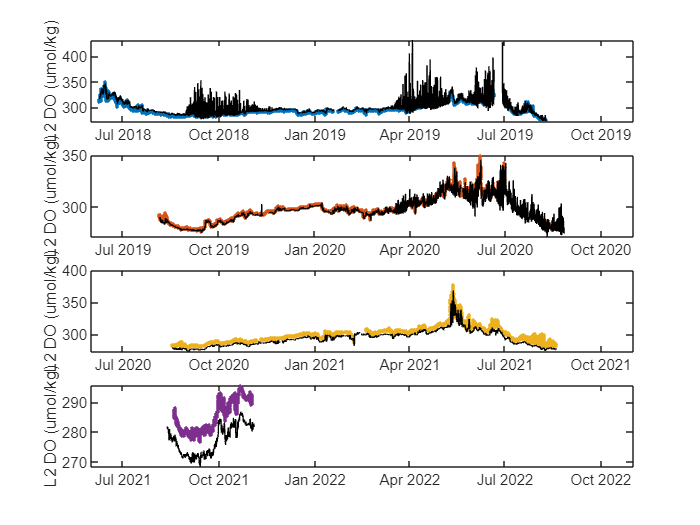

 
%% Load in calibrated CTD profiles and bottle files 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Processed')
load Year6_Processed_KF.mat
[nsif_yr5e, nsif_yr5e_tbl] = AAgain_from_CTDcasts(nsif_DO5,downcasts_yr6,cast_num_yr6,AssetRadius,'NSIF','recovery');
[buoy_yr5e, buoy_yr5e_tbl] = AAgain_from_CTDcasts(buoy_DO5,downcasts_yr6,cast_num_yr6,AssetRadius,'SUMO','recovery');

nsif_yr5e_tbl
buoy_yr5e_tbl

% tbl5 = [nsif_yr5s_tbl; nsif_yr5e_tbl; buoy_yr5s_tbl; buoy_yr5e_tbl];
% to output to excel file 

## Year 5: Make Gain corrections, remove biofouling and merge into mixed-layer product

calcasts =      5
     6


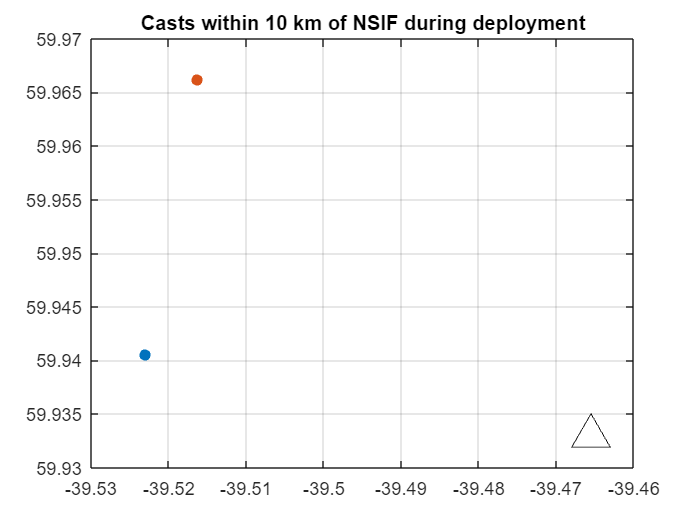

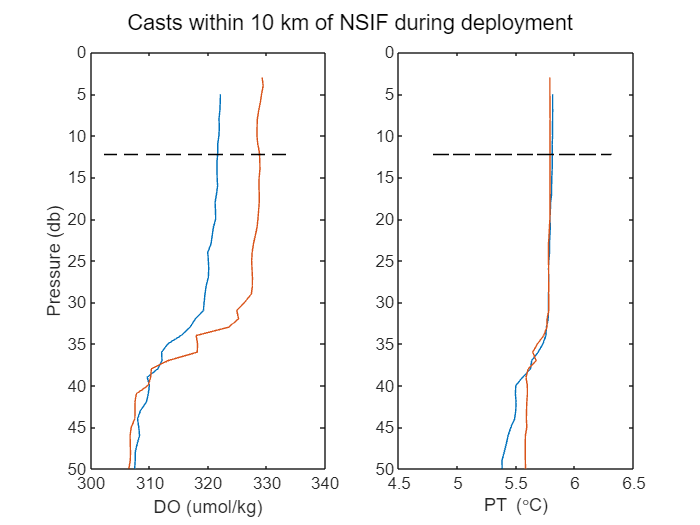

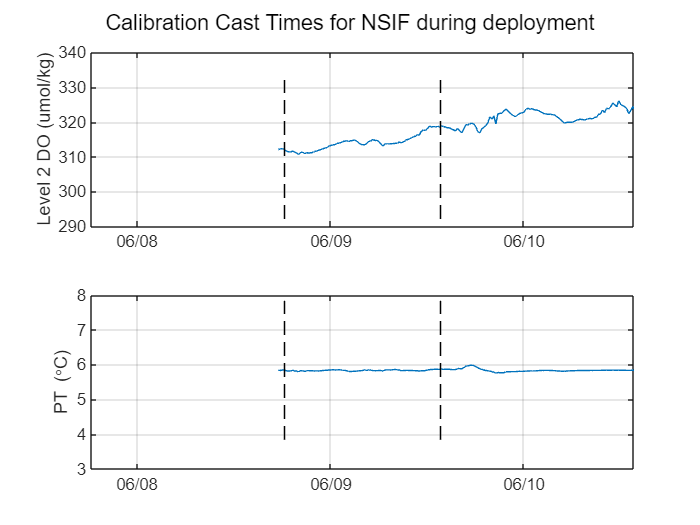

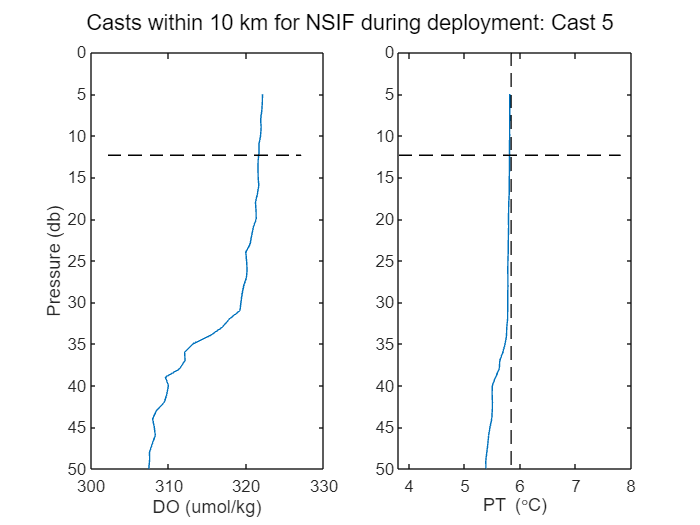

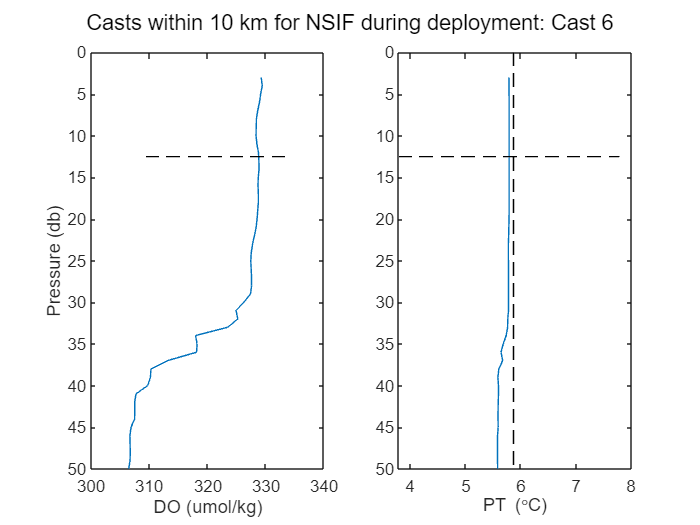

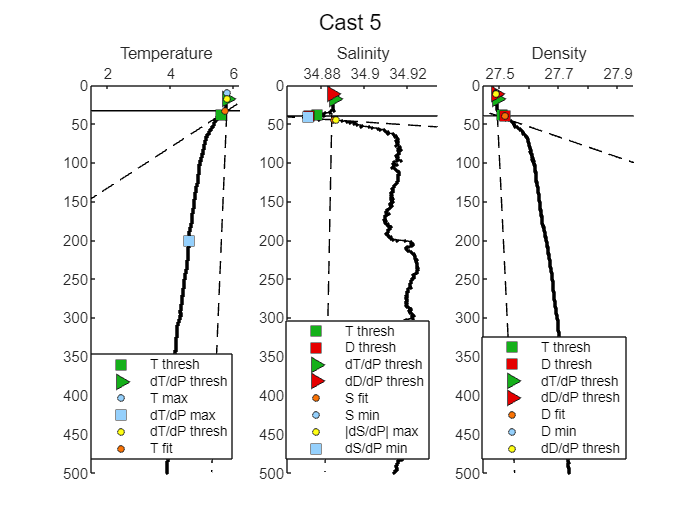

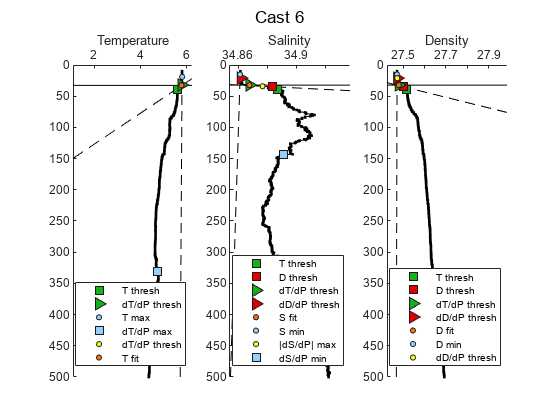

%NSIF gain correction 
gain_deploy = nsif_yr5s_tbl.Gain_Start_DOML(nsif_yr5s_tbl.Cast == 5); 
dt_deploy = nsif_yr5s_tbl.AA_Time(nsif_yr5s_tbl.Cast == 5);

gain_recover = nsif_yr5e_tbl.Gain_Start_DOML(nsif_yr5e_tbl.Cast == 3);

calcasts =      5
     6


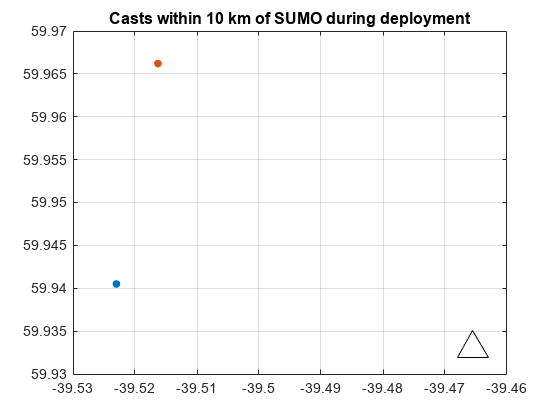

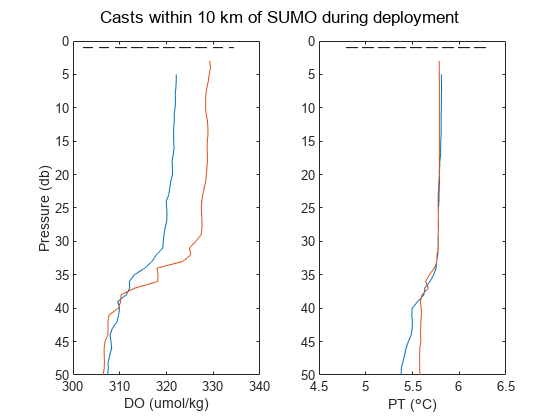

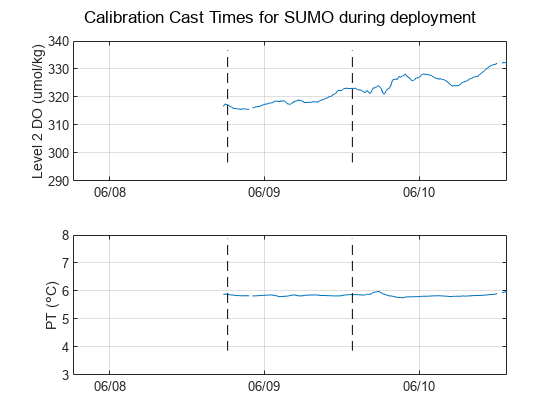

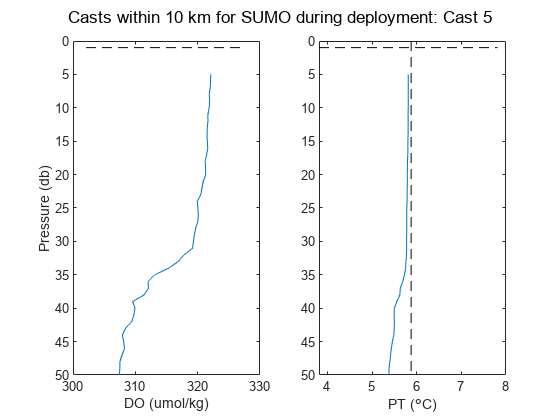

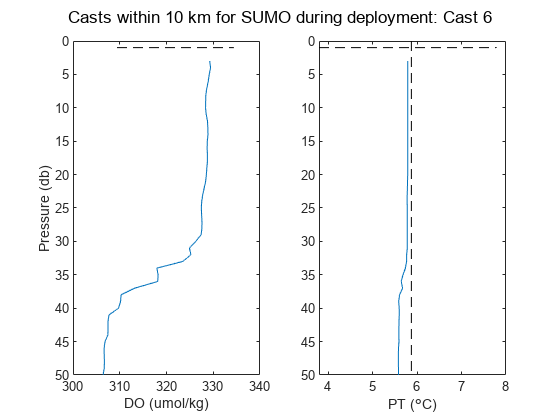

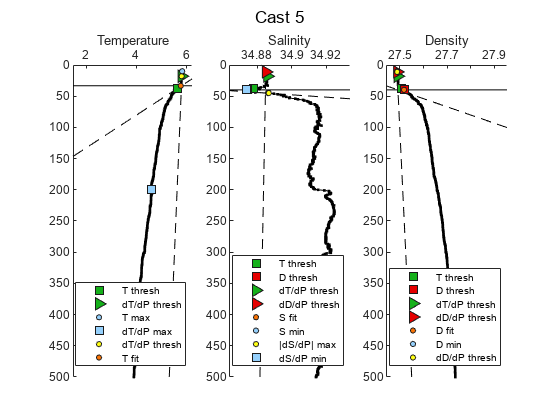

nsif_yr5s_tbl = 2×24 table
    Asset       cal_type      Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    ____________    ____    ____________________    ____________________

dt_recover = nsif_yr5e_tbl.AA_Time(nsif_yr5e_tbl.Cast == 3);

nsif_DO5 = asset_gain_correction(nsif_DO5,gain_deploy,gain_recover,dt_deploy,dt_recover,'NSIF Year 5');

buoy_yr5s_tbl = 2×24 table
    Asset       cal_type      Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    ____________    ____    ____________________    ____________________

calcasts =      3
     9
    11


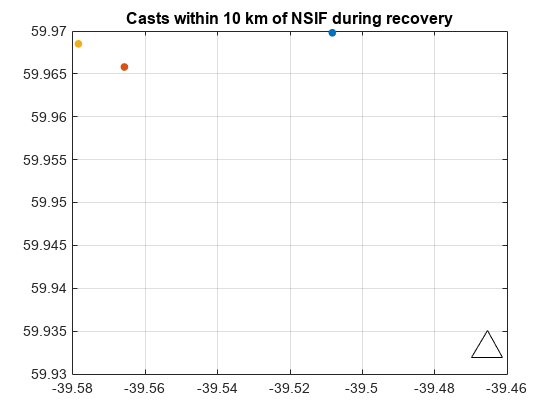

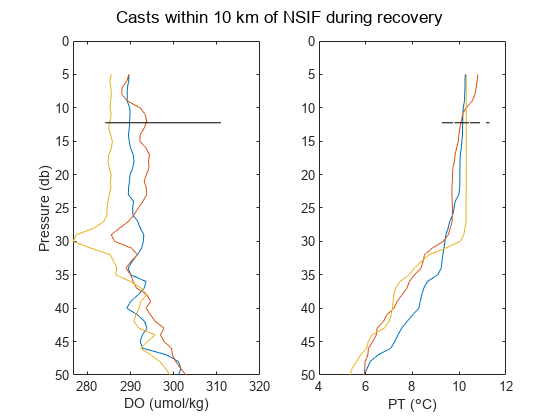

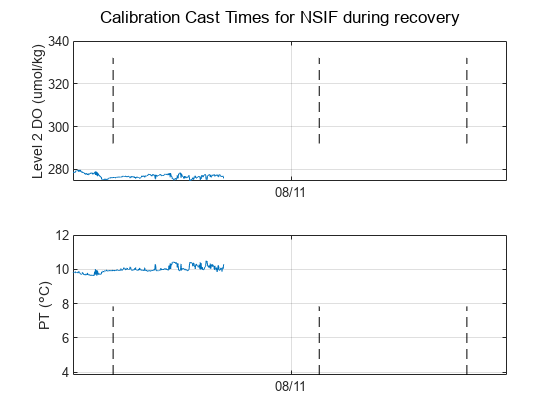

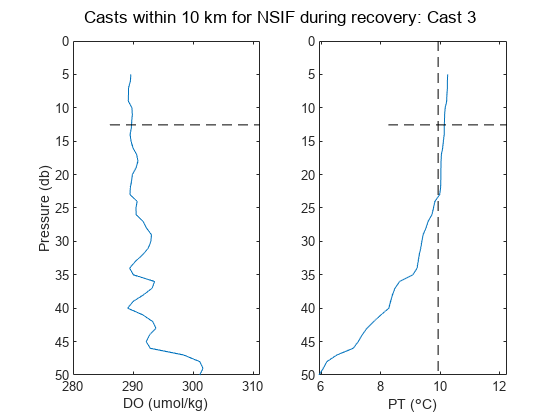

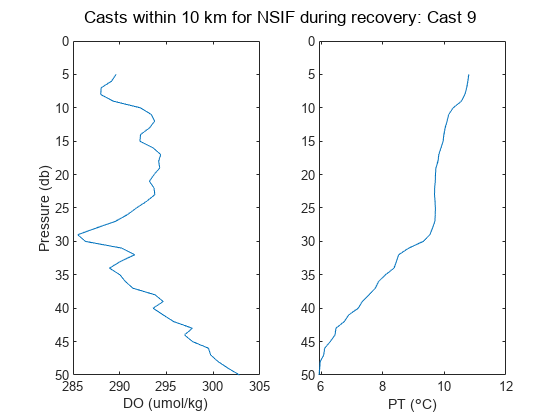

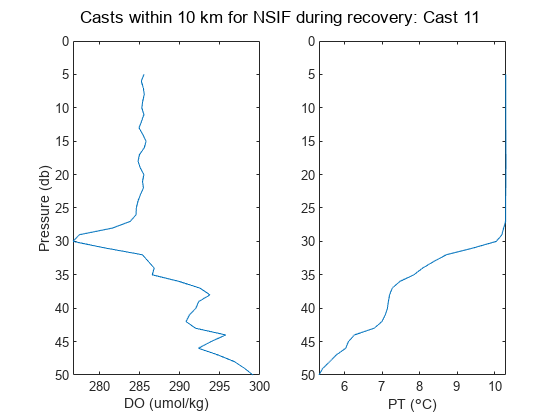

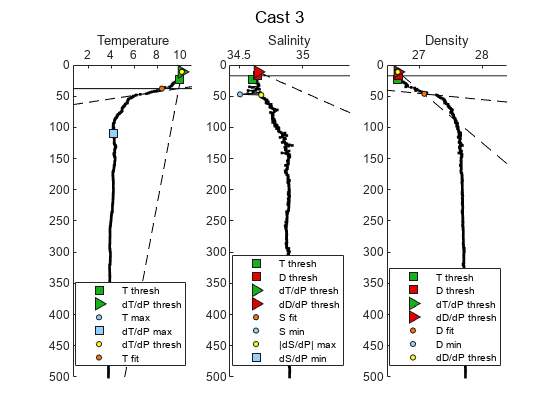

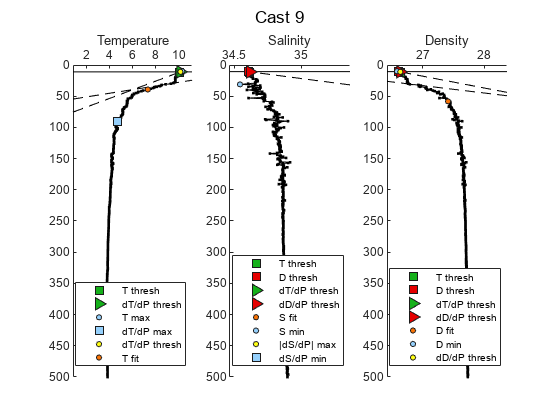


% Buoy gain correction 
gain_deploy = buoy_yr5s_tbl.Gain_Start_DOML(buoy_yr5s_tbl.Cast == 5); 
dt_deploy = buoy_yr5s_tbl.AA_Time(nsif_yr5s_tbl.Cast == 5);

gain_recover = buoy_yr5e_tbl.Gain_Start_DOML(nsif_yr5e_tbl.Cast == 3);

calcasts =      3
     9
    11


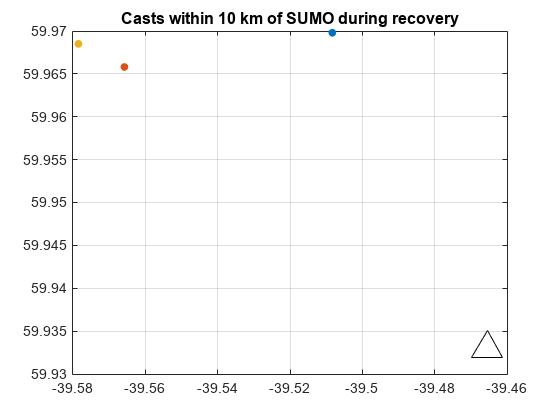

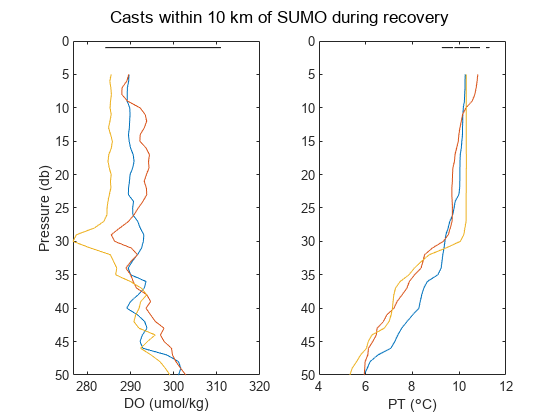

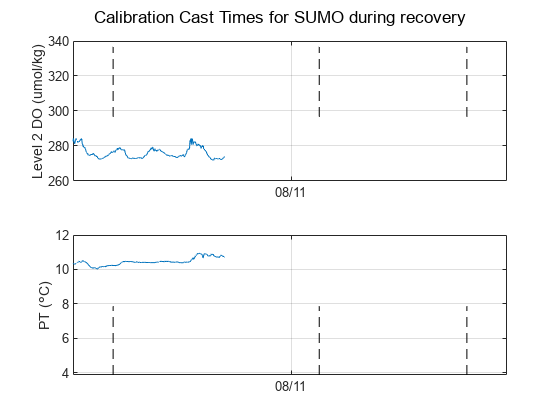

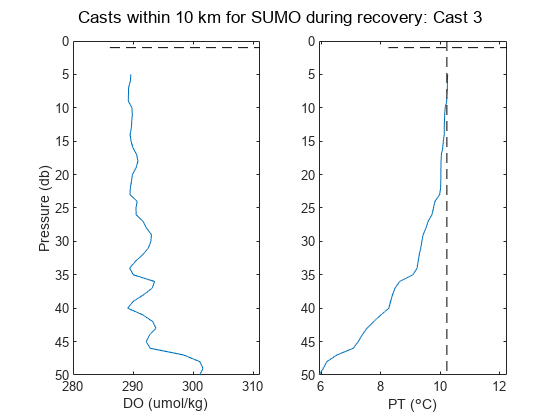

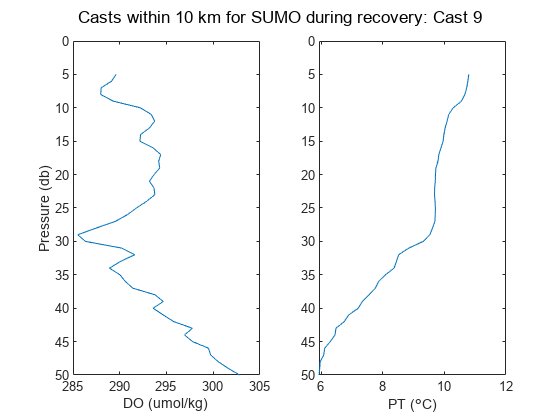

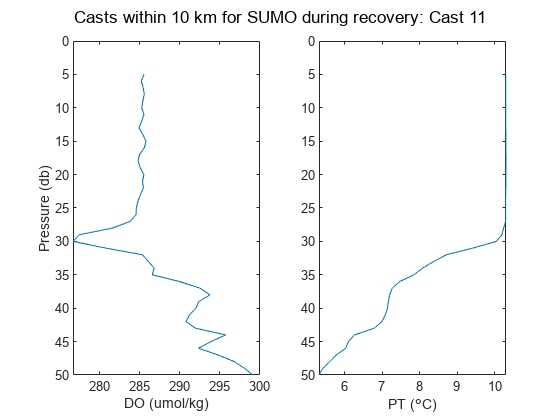

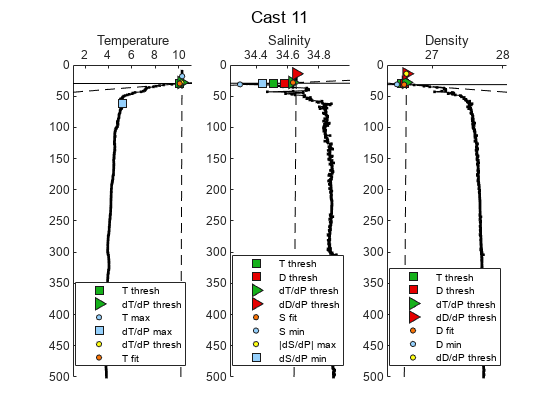

nsif_yr5e_tbl = 3×24 table
    Asset      cal_type     Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    __________    ____    ____________________    ____________________

dt_recover = buoy_yr5e_tbl.AA_Time(nsif_yr5e_tbl.Cast == 3);

buoy_DO5 = asset_gain_correction(buoy_DO5,gain_deploy,gain_recover,dt_deploy,dt_recover,'SUMO Year 5');

buoy_yr5e_tbl = 3×24 table
    Asset      cal_type     Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    __________    ____    ____________________    ____________________

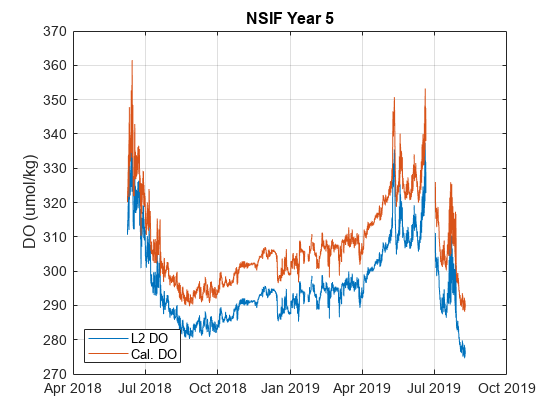

% Remove biofouling 
figure
plot(nsif_DO5.DOdt,nsif_DO5.DOcorr_umolkg,'.')
hold on
plot(buoy_DO5.DOdt,buoy_DO5.DOcorr_umolkg,'k')
ylabel('Calibrated DO (umol/kg)')

% Visually determined biofouling in SUMO data
bf1 = find(buoy_DO5.DOdt > datetime(2018,08,17) & buoy_DO5.DOdt < datetime(2018,12,15));
bf2 = find(buoy_DO5.DOdt > datetime(2019,03,09));

nsif_DO5.DOqaqc_umolkg = nsif_DO5.DOcorr_umolkg; % No biofouling signal
buoy_DO5.DOqaqc_umolkg = buoy_DO5.DOcorr_umolkg; 

buoy_DO5.DOqaqc_umolkg(bf1) = NaN;
buoy_DO5.DOqaqc_umolkg(bf2) = NaN;

figure
plot(nsif_DO5.DOdt,nsif_DO5.DOqaqc_umolkg,'.')
hold on
plot(buoy_DO5.DOdt,buoy_DO5.DOqaqc_umolkg,'k')
ylabel('Calibrated DO (umol/kg)')

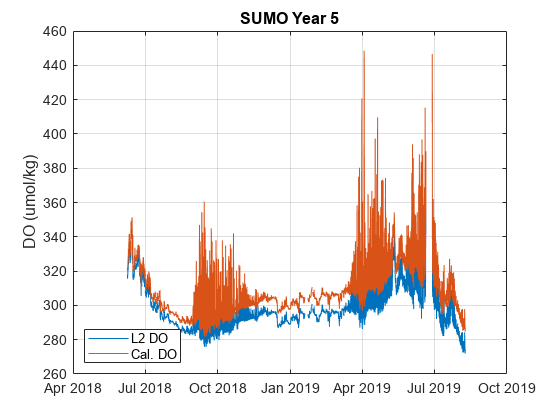

% Take mean of sumo/nsif to create mixed layer product 

ML_DO5 = merge_DOassets_TT(nsif_DO5,buoy_DO5,'mean');


## Deployment 6 DO Calibration 

#### Calculate AA gain at beginning of deployment

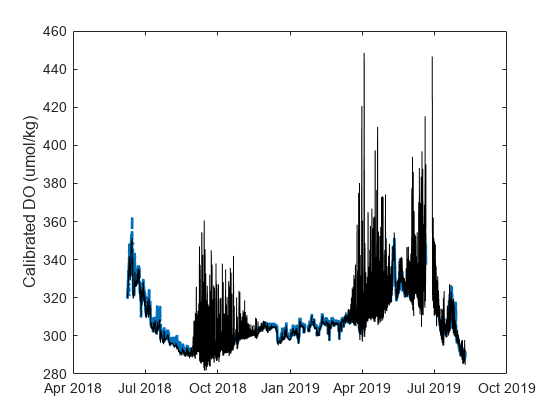


[nsif_yr6s, nsif_yr6s_tbl] = AAgain_from_CTDcasts(nsif_DO6,downcasts_yr6,cast_num_yr6,AssetRadius,'NSIF','deployment'); % start
[buoy_yr6s, buoy_yr6s_tbl] = AAgain_from_CTDcasts(buoy_DO6,downcasts_yr6,cast_num_yr6,AssetRadius,'SUMO','deployment'); % start
nsif_yr6s_tbl
buoy_yr6s_tbl

#### Calculate AA gain at end of deployment

%% Load in calibrated CTD profiles and bottle files 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Processed')
load Year7_Processed_KF.mat
[nsif_yr6e, nsif_yr6e_tbl] = AAgain_from_CTDcasts(nsif_DO6,downcasts_yr7,cast_num_yr7,AssetRadius,'NSIF','recovery'); % end
[buoy_yr6e, buoy_yr6e_tbl] = AAgain_from_CTDcasts(buoy_DO6,downcasts_yr7,cast_num_yr7,AssetRadius,'SUMO','recovery'); % end
nsif_yr6e_tbl
buoy_yr6e_tbl


tbl6 = [nsif_yr6s_tbl; nsif_yr6e_tbl; buoy_yr6s_tbl; buoy_yr6e_tbl];

## Year 6: Make Gain corrections, remove biofouling, and create mixed layer DO product 

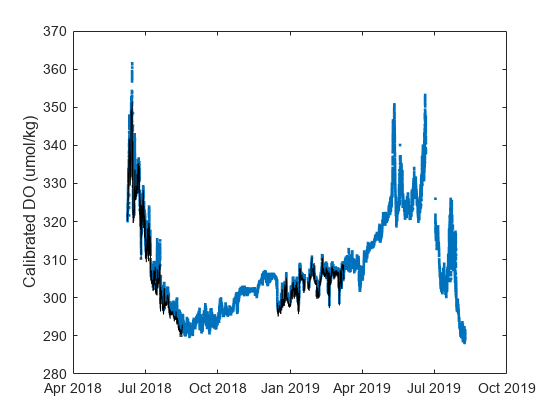

%NSIF
gain_deploy = nsif_yr6s_tbl.Gain_Start_DOML(nsif_yr6s_tbl.Cast == 11); 
dt_deploy = nsif_yr6s_tbl.AA_Time(nsif_yr6s_tbl.Cast == 11);


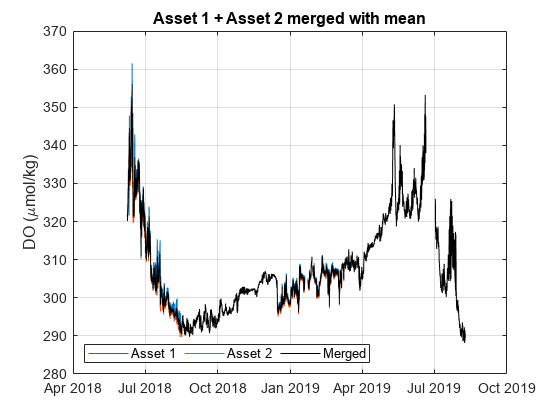

gain_recover = nsif_yr6e_tbl.Gain_Start_DOML(nsif_yr6e_tbl.Cast == 9);
dt_recover = nsif_yr6e_tbl.AA_Time(nsif_yr6e_tbl.Cast == 9);
nsif_DO6 = asset_gain_correction(nsif_DO6,gain_deploy,gain_recover,dt_deploy,dt_recover,'NSIF Year 6');

calcasts =      3
     9
    11


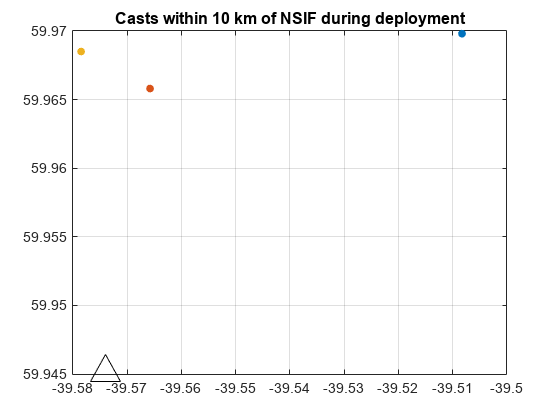

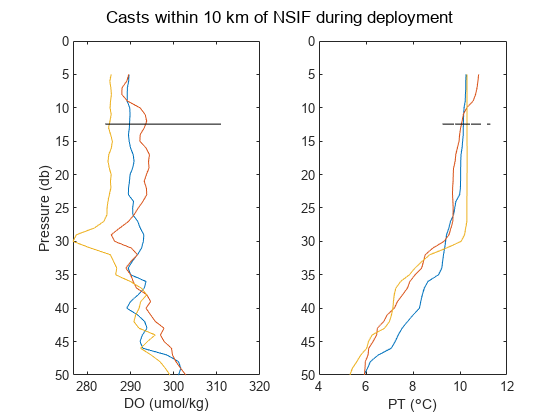

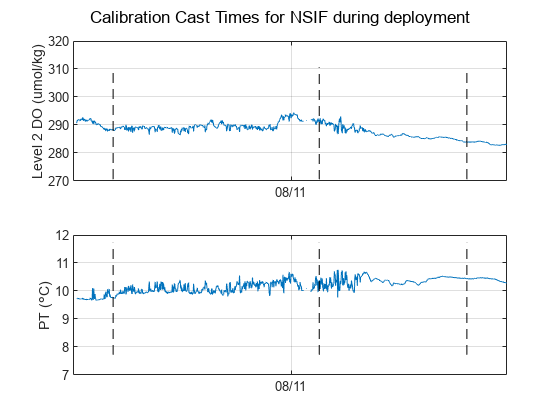

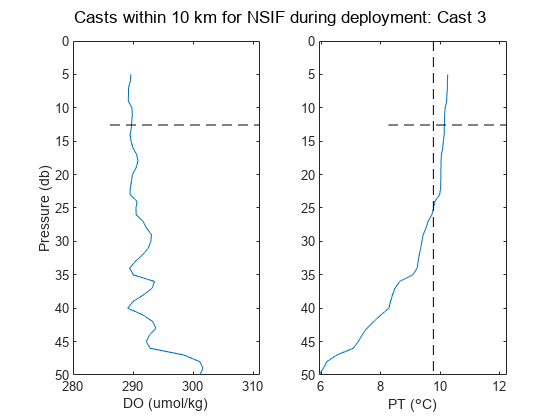

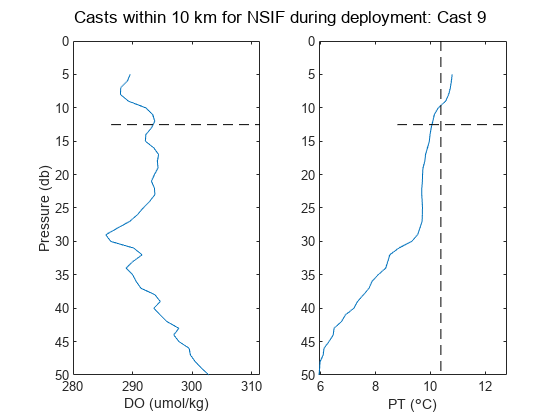

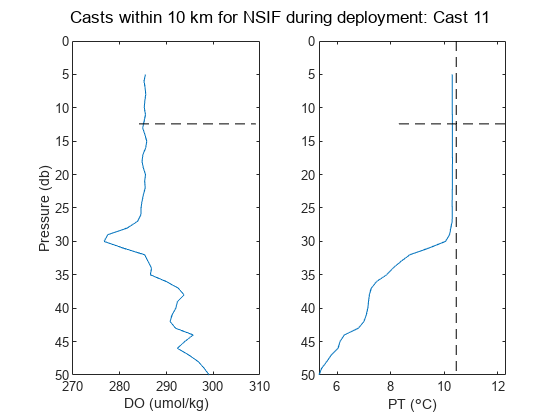

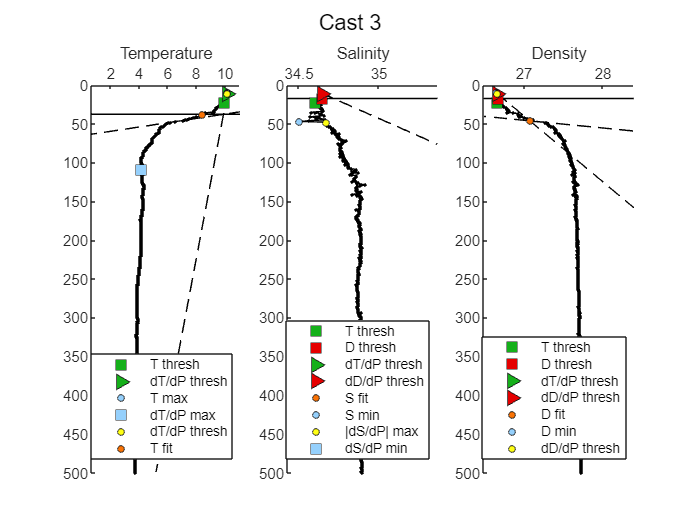


% Buoy
gain_deploy = buoy_yr6s_tbl.Gain_Start_DOML(buoy_yr6s_tbl.Cast == 11); 
dt_deploy = buoy_yr6s_tbl.AA_Time(buoy_yr6s_tbl.Cast == 11);

%% Use nsif to calculate gain before biofouling begins

calcasts =      3
     9
    11


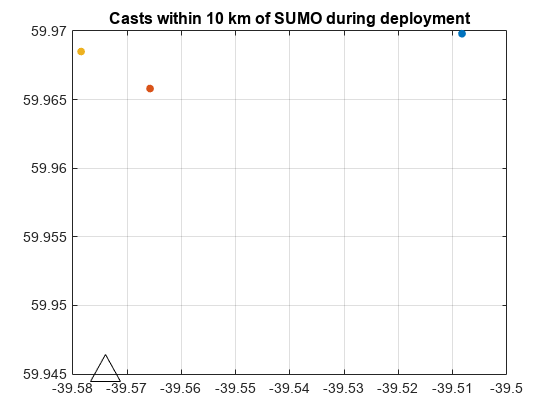

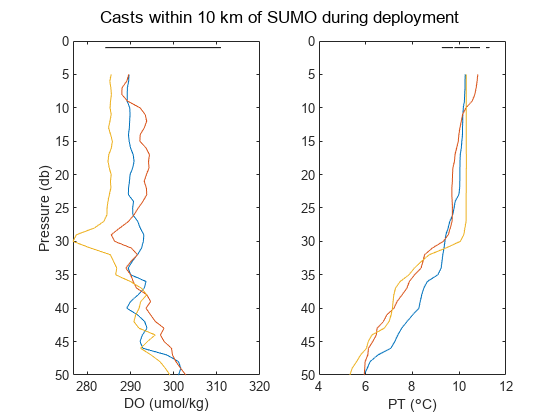

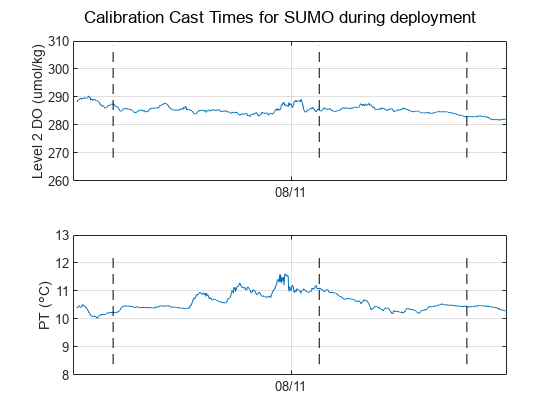

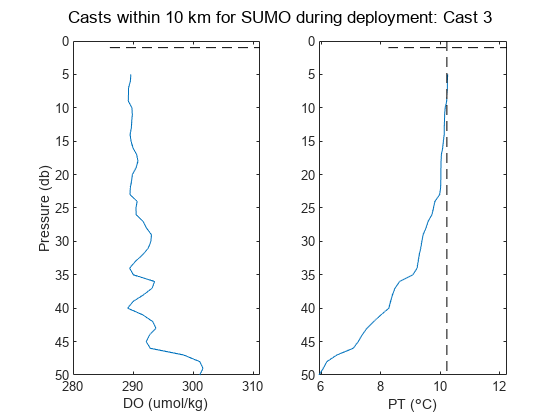

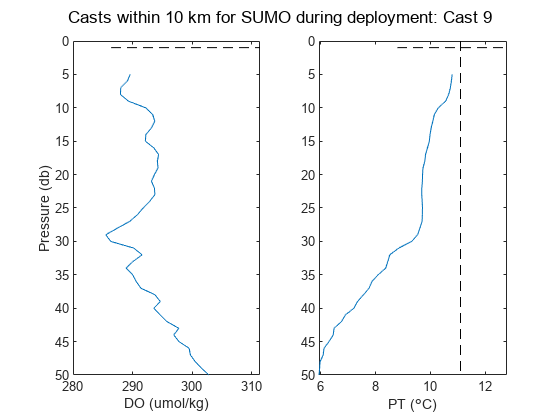

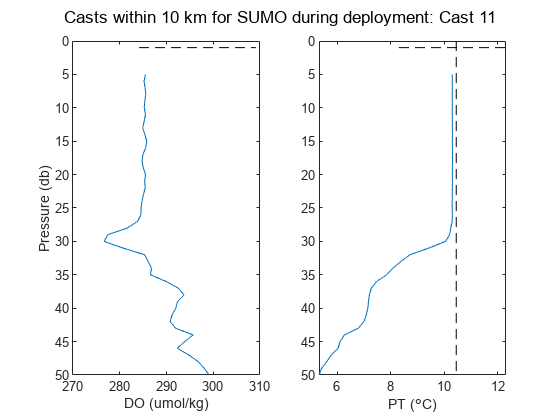

% period of time before biofouling to use as drift correction for buoy 

bgain_ind = find(buoy_DO6.DOdt > datetime(2020,02,17) & buoy_DO6.DOdt < datetime(2020,02,18,18,00,00));

nsif_yr6s_tbl = 3×24 table
    Asset       cal_type      Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    ____________    ____    ____________________    ____________________

ngain_ind = find(nsif_DO6.DOdt > datetime(2020,02,17) & nsif_DO6.DOdt < datetime(2020,02,18,18,00,00));

buoy_yr6s_tbl = 3×24 table
    Asset       cal_type      Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    ____________    ____    ____________________    ____________________

calcasts =      2
     5
     7
     8
     9
    18
    19


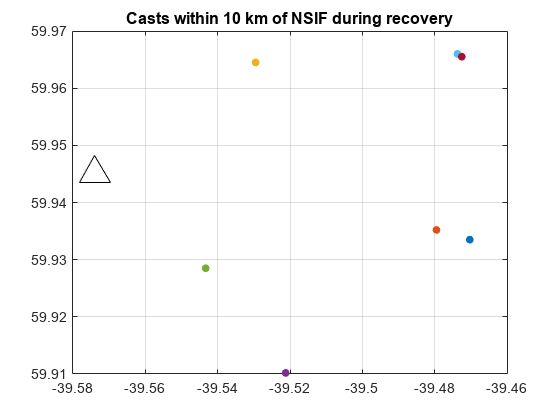

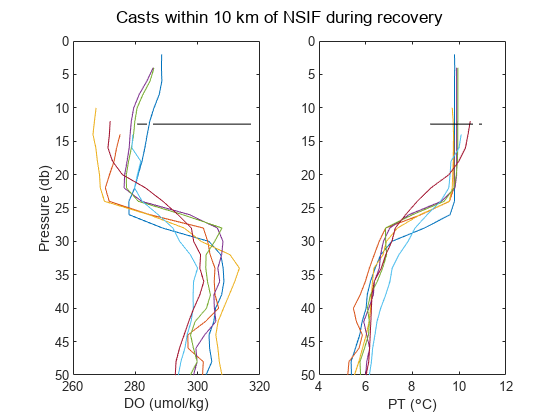

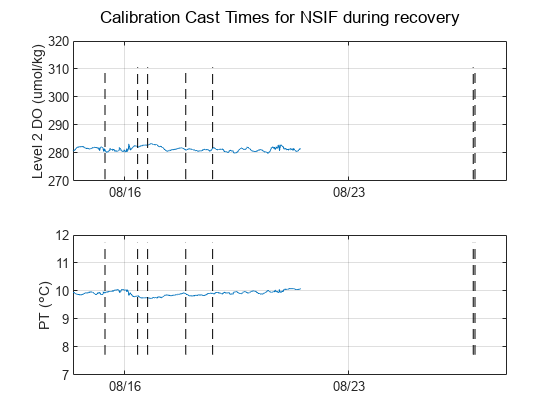

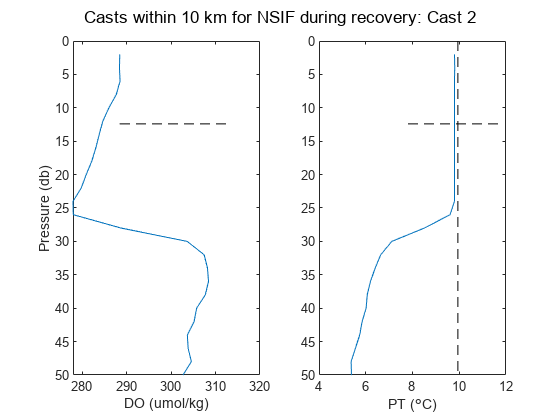

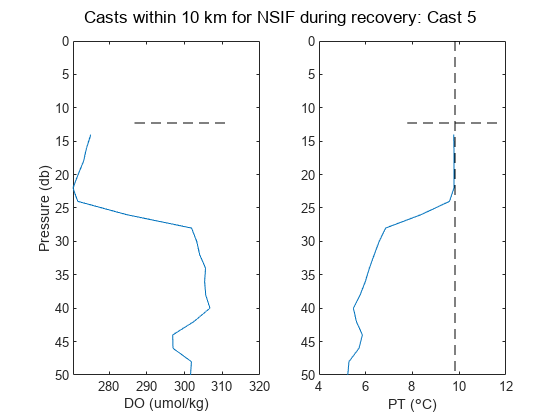

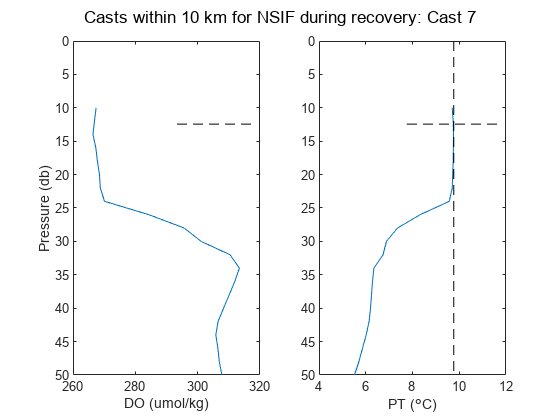

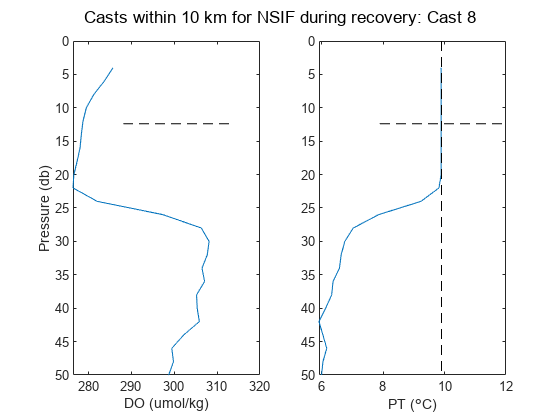

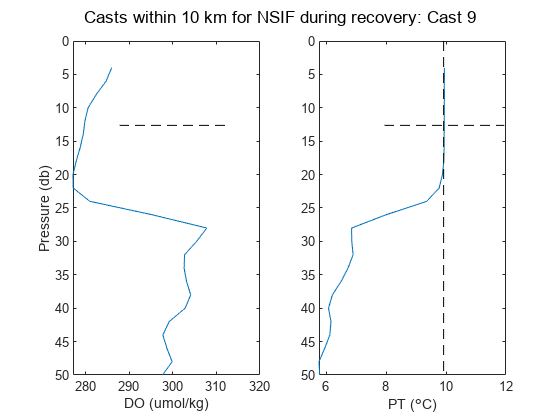


figure
plot(nsif_DO6.DOdt(ngain_ind),movmean(nsif_DO6.DOcorr_umolkg(ngain_ind),4))
hold on
plot(buoy_DO6.DOdt(bgain_ind),movmean(buoy_DO6.dissolved_oxygen(bgain_ind),4))

calcasts =      2
     5
     7
     8
     9
    18
    19


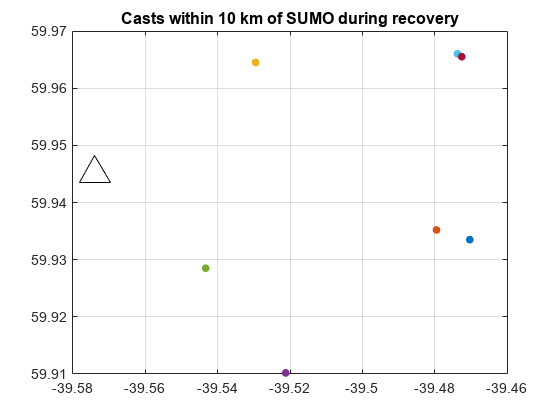

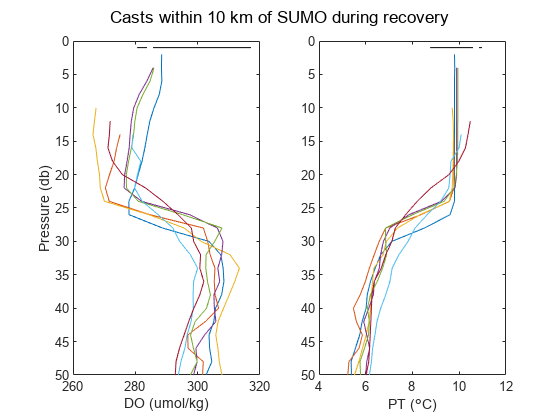

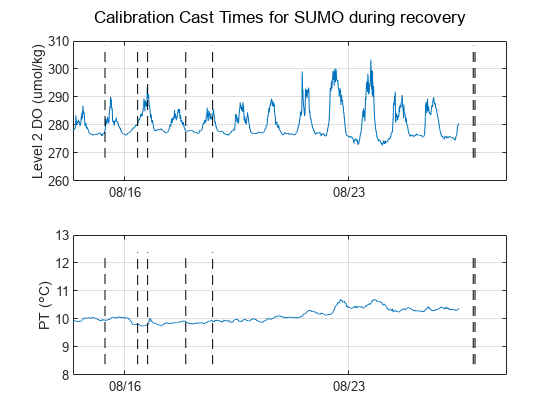

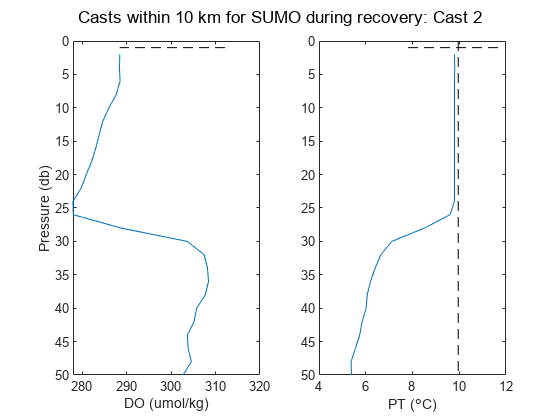

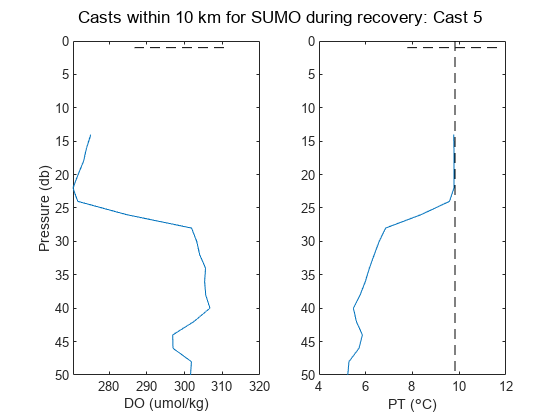

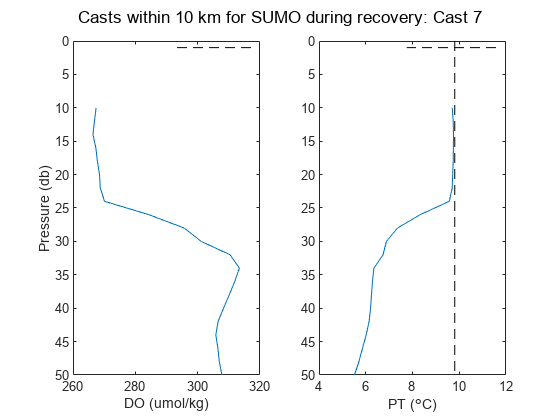

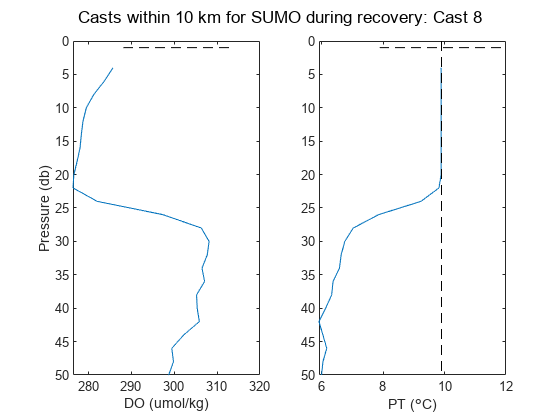

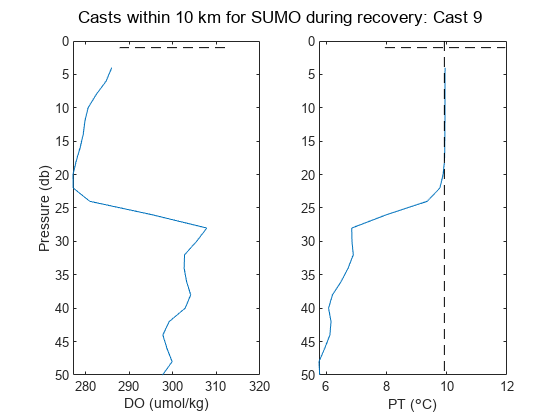

nsif_yr6e_tbl = 7×24 table
    Asset      cal_type     Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    __________    ____    ____________________    ____________________

title('NSIF vs Buoy for end gain calculation')

figure

buoy_yr6e_tbl = 7×24 table
    Asset      cal_type     Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    __________    ____    ____________________    ____________________

plot(movmean(nsif_DO6.DOcorr_umolkg(ngain_ind),4)./movmean(buoy_DO6.dissolved_oxygen(bgain_ind),4))
dt_recover = nanmean(buoy_DO6.DOdt(bgain_ind))
gain_recover = nanmean(nsif_DO6.DOcorr_umolkg(ngain_ind)./buoy_DO6.dissolved_oxygen(bgain_ind))
gain_std = nanstd(nsif_DO6.DOcorr_umolkg(ngain_ind)./buoy_DO6.dissolved_oxygen(bgain_ind))
title('gain correction before biofouling')

buoy_DO6 = asset_gain_correction(buoy_DO6,gain_deploy,gain_recover,dt_deploy,dt_recover,'SUMO Year 6');

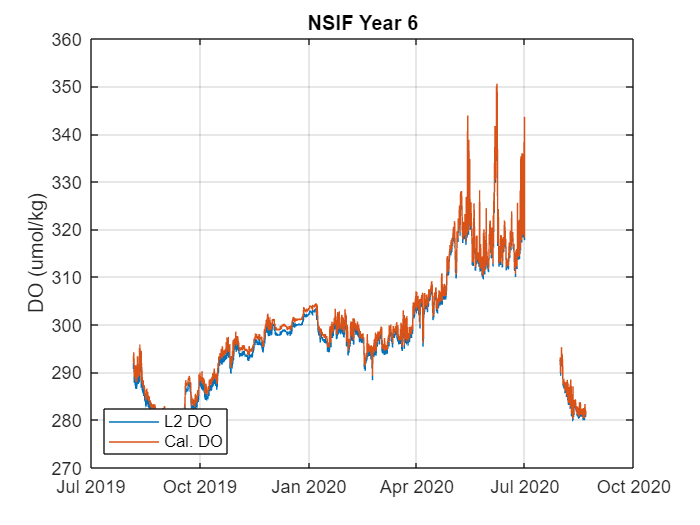

% Remove biofouling 
figure
plot(nsif_DO6.DOdt,nsif_DO6.DOcorr_umolkg,'.')
hold on
plot(buoy_DO6.DOdt,buoy_DO6.DOcorr_umolkg,'k')

ylabel('Calibrated DO (umol/kg)')

% Visually determined biofouling in SUMO data
bf1 = find(buoy_DO6.DOdt > datetime(2020,02,27));

nsif_DO6.DOqaqc_umolkg = nsif_DO6.DOcorr_umolkg; % No biofouling signal
buoy_DO6.DOqaqc_umolkg = buoy_DO6.DOcorr_umolkg; 
buoy_DO6.DOqaqc_umolkg(bf1) = NaN;

figure
plot(nsif_DO6.DOdt,nsif_DO6.DOqaqc_umolkg,'.')
hold on
plot(buoy_DO6.DOdt,buoy_DO6.DOqaqc_umolkg,'k')
ylabel('Calibrated DO (umol/kg)')

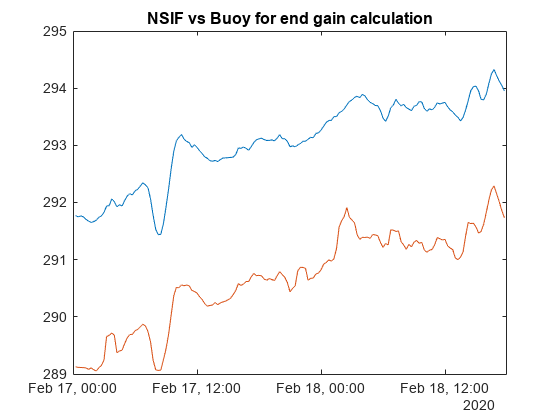

% Take mean of sumo/nsif to create mixed layer product 

ML_DO6 = merge_DOassets_TT(nsif_DO6,buoy_DO6,'mean');


## Deployment 7 DO Calibration 

#### Calculate AA gain at beginning of deployment

[nsif_yr7s, nsif_yr7s_tbl] = AAgain_from_CTDcasts(nsif_DO7,downcasts_yr7,cast_num_yr7,AssetRadius,'NSIF','deployment'); % start
[buoy_yr7s, buoy_yr7s_tbl] = AAgain_from_CTDcasts(buoy_DO7,downcasts_yr7,cast_num_yr7,AssetRadius,'SUMO','deployment'); % start

dt_recover = datetime
   17-Feb-2020 21:00:00


nsif_yr7s_tbl

gain_recover = 1.0082

buoy_yr7s_tbl

gain_std = 8.2687e-04

#### Calculate AA gain at end of deployment

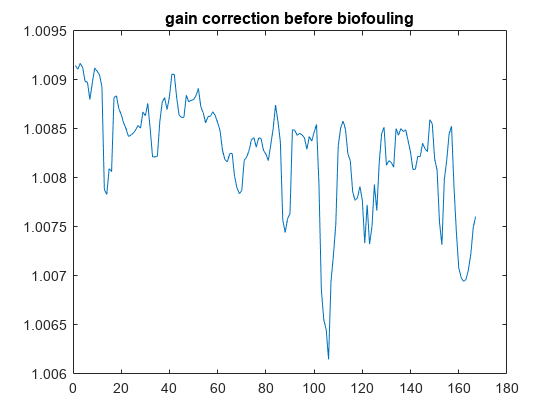

%% Load in calibrated CTD profiles and bottle files 

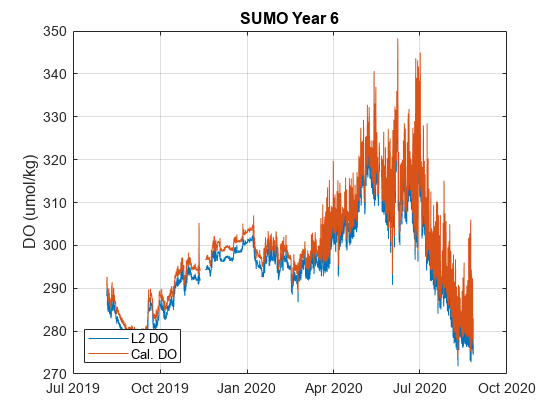

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Processed')
load Year8_Processed_KF.mat

[nsif_yr7e, nsif_yr7e_tbl] = AAgain_from_CTDcasts(nsif_DO7,downcasts_yr8,cast_num_yr8,AssetRadius,'NSIF','recovery'); % end
[buoy_yr7e, buoy_yr7e_tbl] = AAgain_from_CTDcasts(buoy_DO7,downcasts_yr8,cast_num_yr8,AssetRadius,'SUMO','recovery'); % end
nsif_yr7e_tbl
buoy_yr7e_tbl

% tbl7 = [nsif_yr7s_tbl; nsif_yr7e_tbl; buoy_yr7s_tbl; buoy_yr7e_tbl];

## Year 7: Make Gain corrections

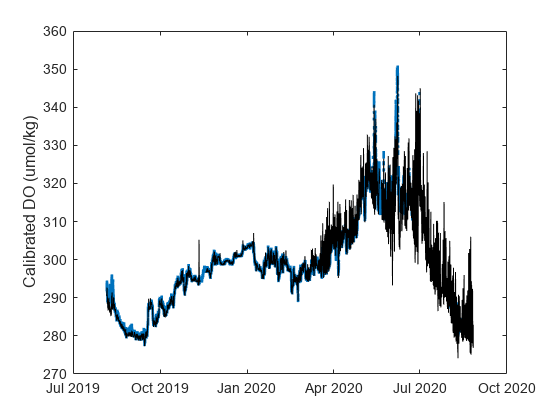

% Buoy
gain_deploy = buoy_yr7s_tbl.Gain_Start_DOML(buoy_yr7s_tbl.Cast == 9); 

dt_deploy = buoy_yr7s_tbl.AA_Time(buoy_yr7s_tbl.Cast == 9);

gain_recover = buoy_yr7e_tbl.Gain_Start_DOML(buoy_yr7e_tbl.Cast == 5);
dt_recover = buoy_yr7e_tbl.AA_Time(buoy_yr7e_tbl.Cast == 5);

buoy_DO7 = asset_gain_correction(buoy_DO7,gain_deploy,gain_recover,dt_deploy,dt_recover,'SUMO Year 7');

%NSIF
gain_deploy = nsif_yr7s_tbl.Gain_Start_DOML(nsif_yr7s_tbl.Cast == 9); 
dt_deploy = nsif_yr7s_tbl.AA_Time(nsif_yr7s_tbl.Cast == 9);

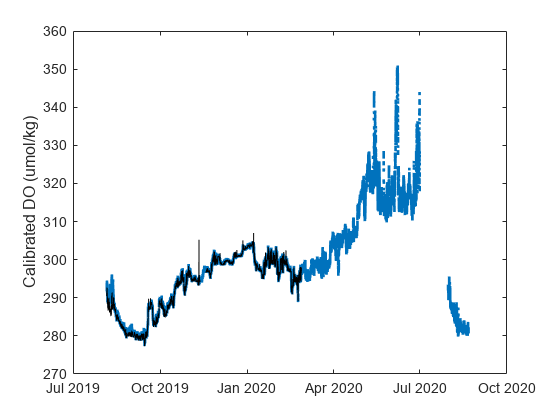


%% Use buoy to calculate gain before biofouling begins
% period of time before biofouling to use as drift correction for nsif

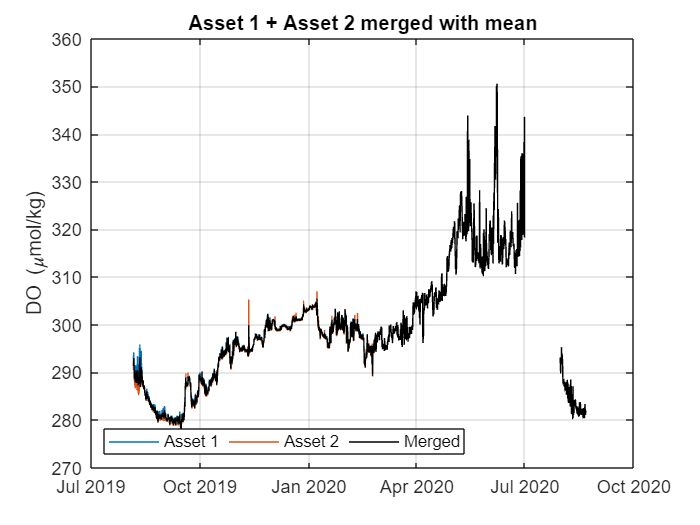

bgain_ind = find(buoy_DO7.DOdt > datetime(2021,07,6) & buoy_DO7.DOdt < datetime(2021,07,7,00,00,00));
ngain_ind = find(nsif_DO7.DOdt > datetime(2021,07,6) & nsif_DO7.DOdt < datetime(2021,07,7,00,00,00));


calcasts =      8
     9
    18
    19


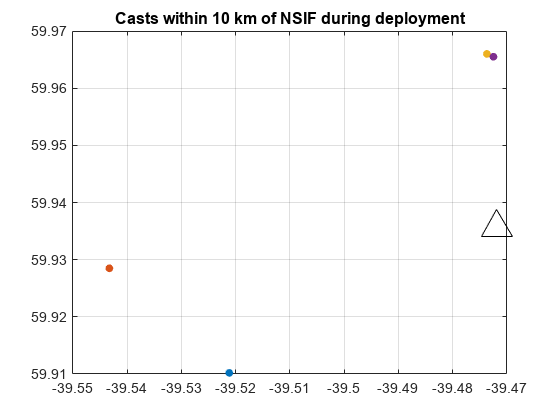

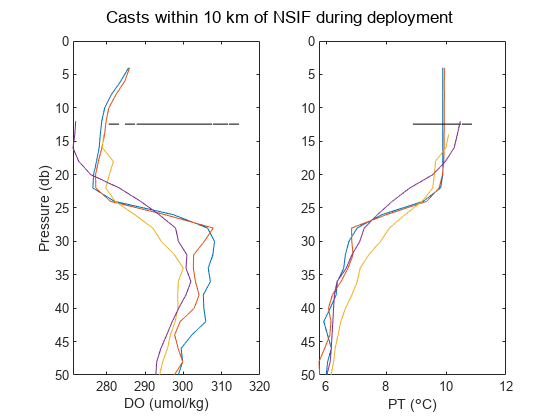

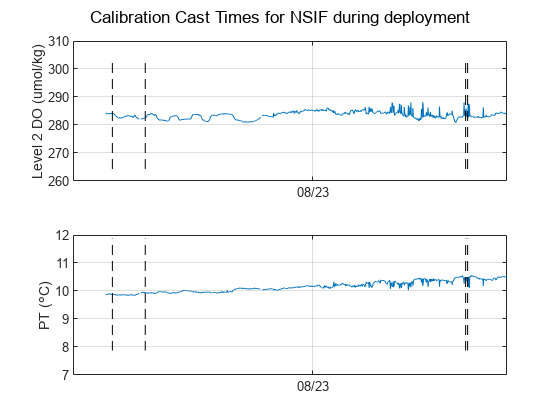

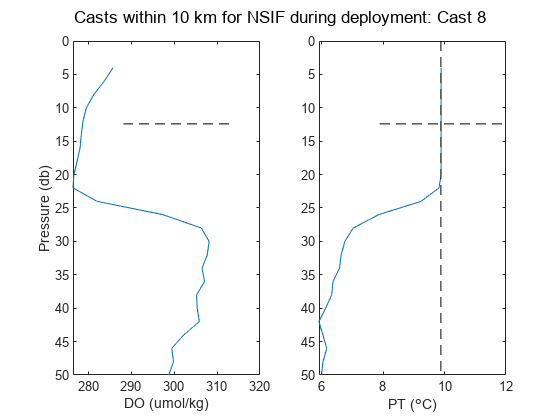

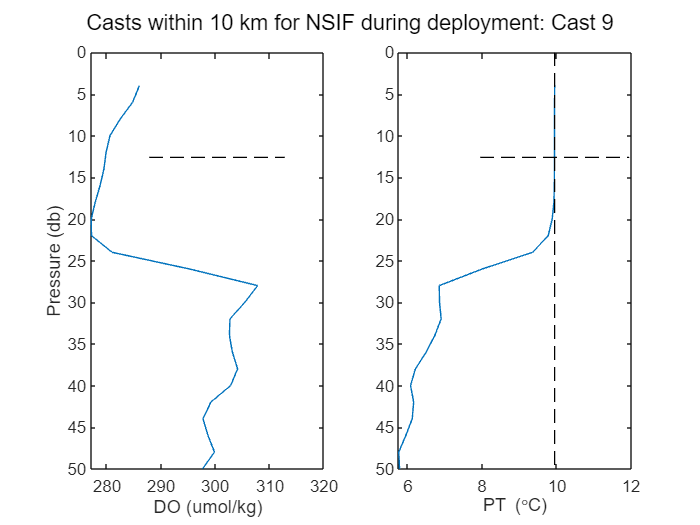

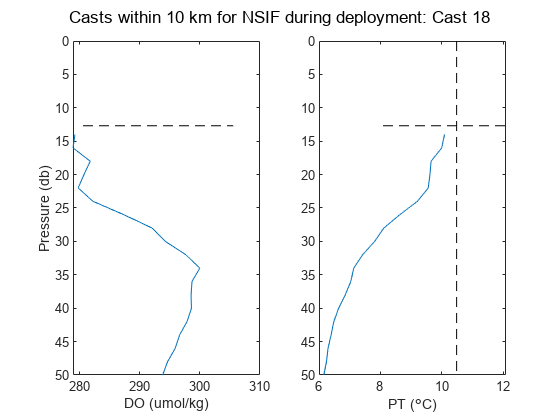

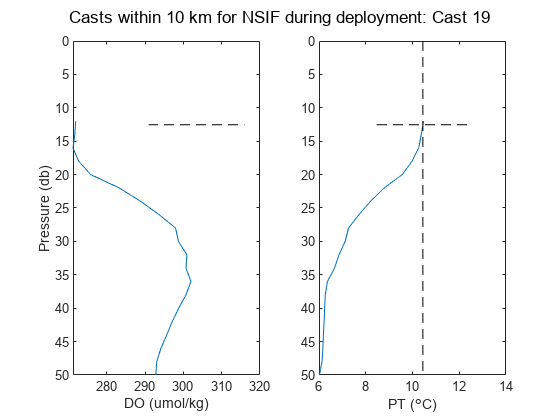

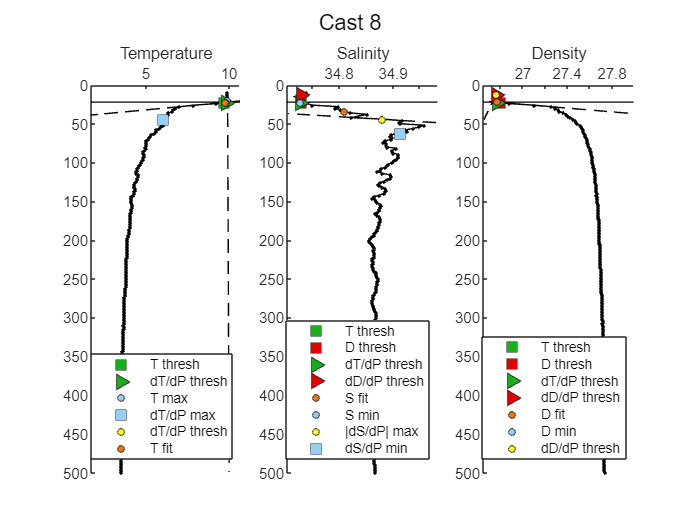

figure
subplot(2,1,1)
plot(nsif_DO7.DOdt(ngain_ind),movmean(nsif_DO7.dissolved_oxygen(ngain_ind),4),'Linewidth',1.5)
hold on
plot(buoy_DO7.DOdt(bgain_ind),movmean(buoy_DO7.DOcorr_umolkg(bgain_ind),4),'Linewidth',1.5)

calcasts =      8
     9
    18
    19


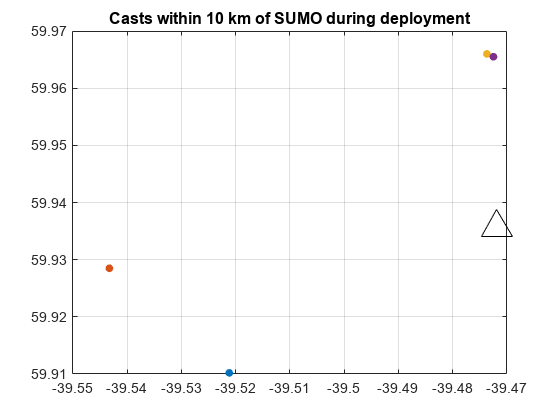

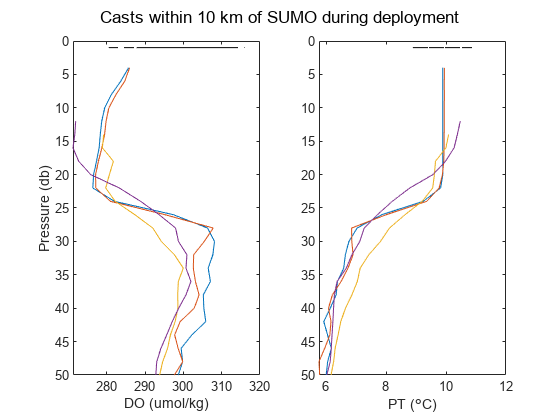

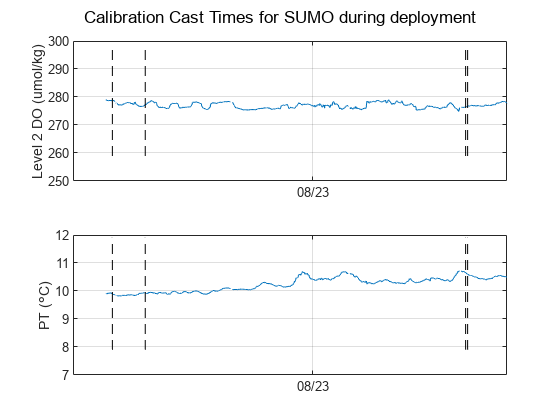

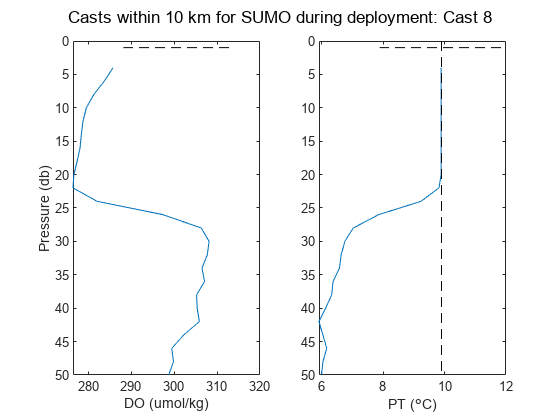

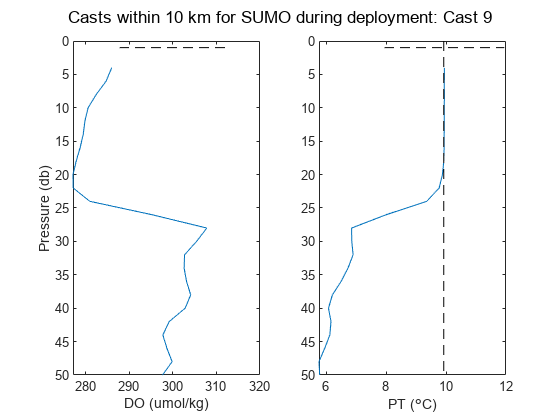

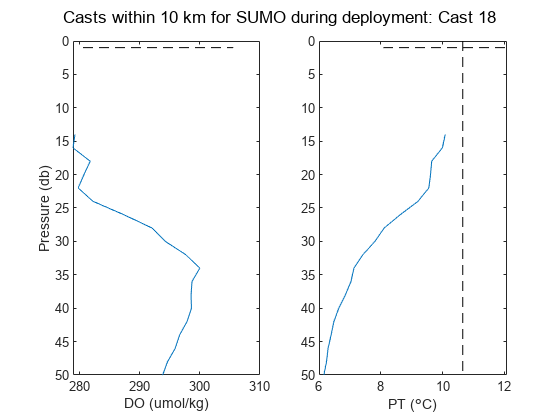

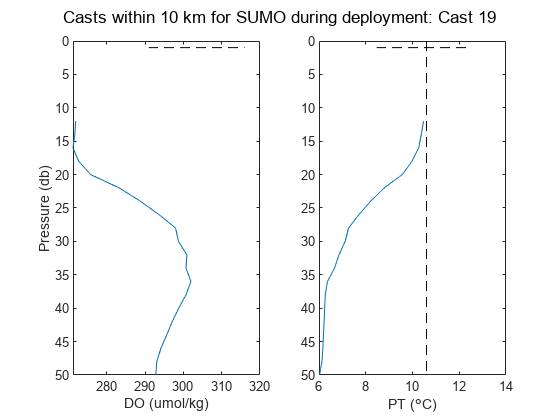

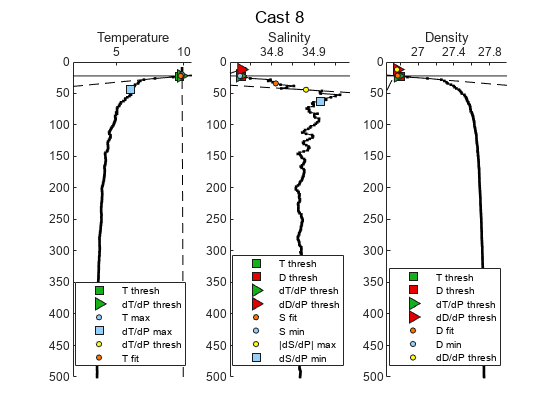

legend('L2-NSIF','Calibrated SUMO','Orientation','horizontal','Location','NE')

ylabel('DO (\mumol kg^-^1)')

nsif_yr7s_tbl = 4×24 table
    Asset       cal_type      Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    ____________    ____    ____________________    ____________________

grid on

buoy_yr7s_tbl = 4×24 table
    Asset       cal_type      Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    ____________    ____    ____________________    ____________________

calcasts =      5
     6


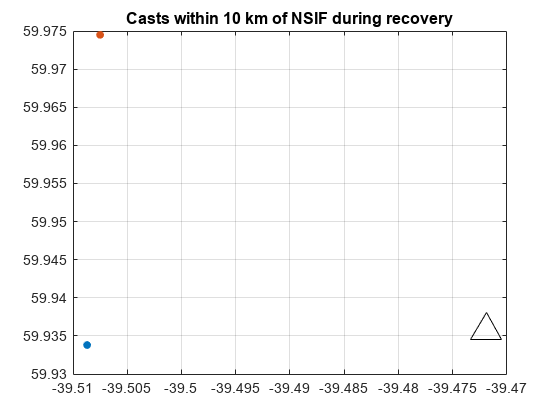

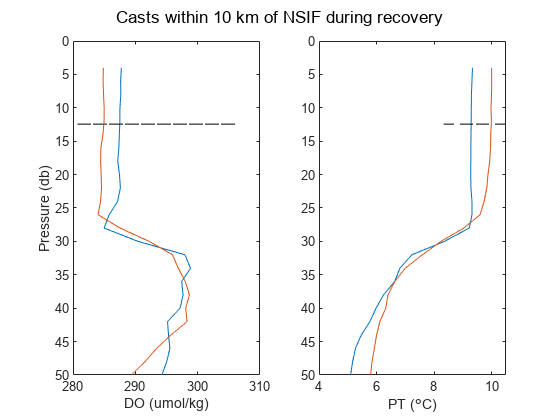

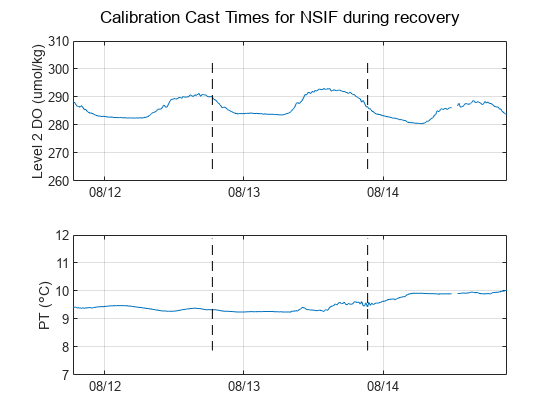

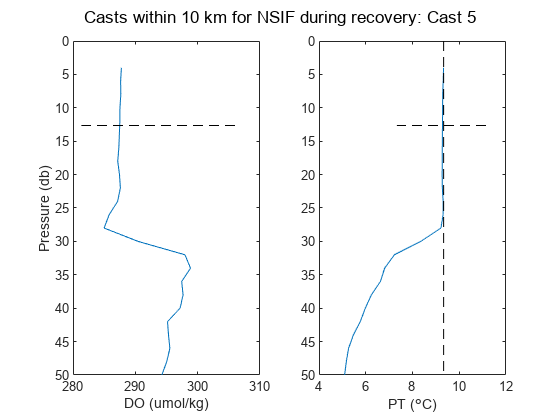

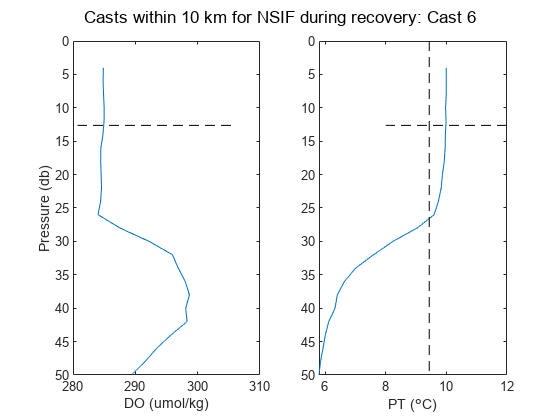

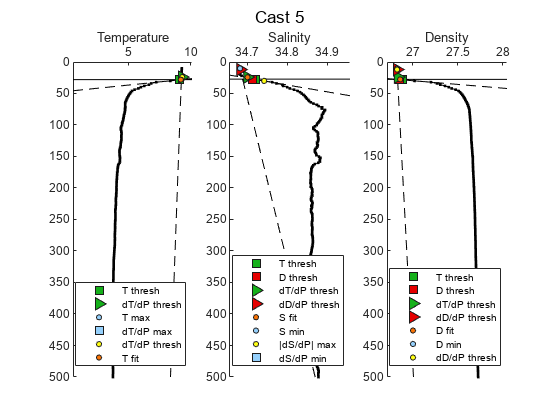

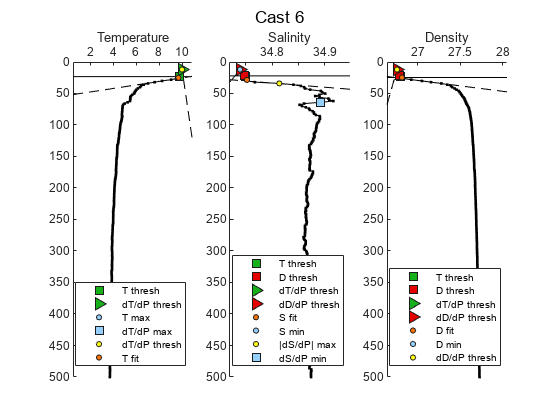


subplot(2,1,2)
plot(nsif_DO7.DOdt(ngain_ind),movmean(buoy_DO7.DOcorr_umolkg(bgain_ind),4)./movmean(nsif_DO7.dissolved_oxygen(ngain_ind),4),'Linewidth',1.5)
ylabel('gain (SUMO/NSIF)')
ylim([1.0080 1.0095])

calcasts =      5
     6


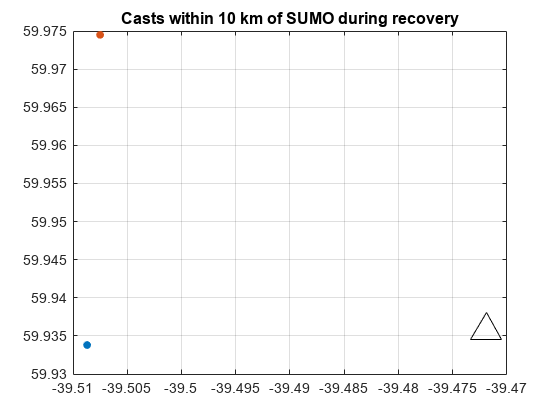

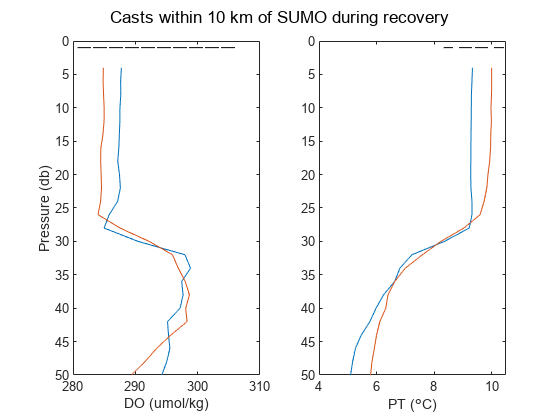

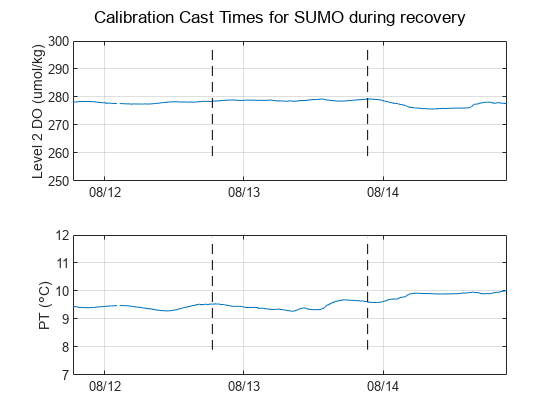

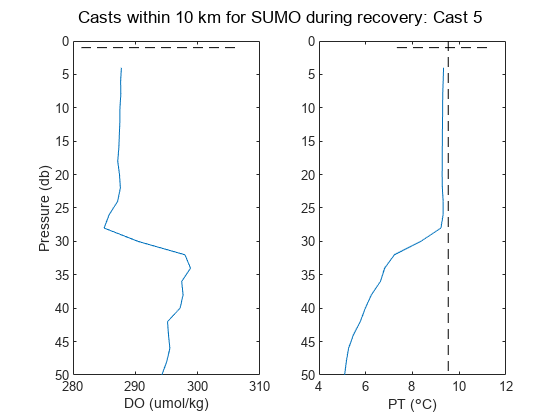

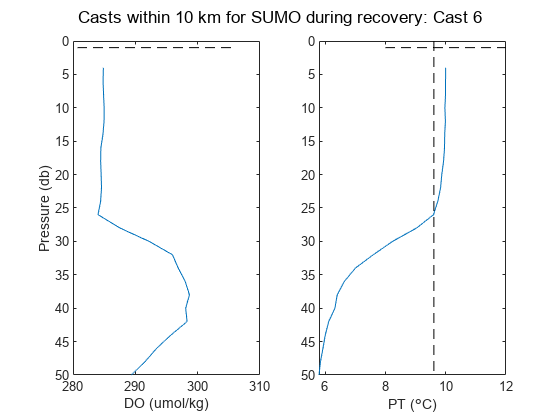

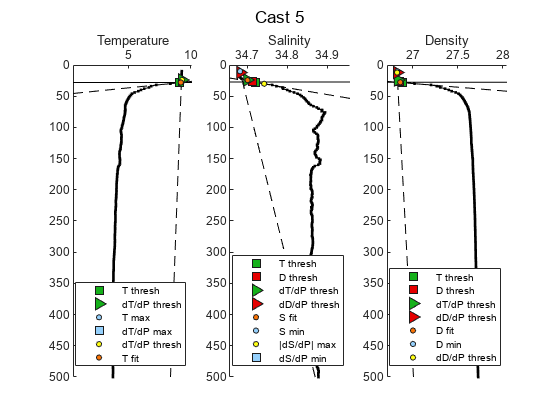

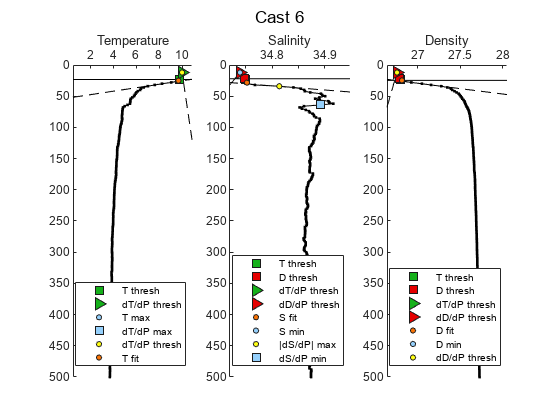

sgtitle('Deployment 7')

grid on

nsif_yr7e_tbl = 2×24 table
    Asset      cal_type     Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    __________    ____    ____________________    ____________________

buoy_yr7e_tbl = 2×24 table
    Asset      cal_type     Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    __________    ____    ____________________    ____________________

dt_recover = nanmean(buoy_DO7.DOdt(bgain_ind))
gain_recover = nanmean(buoy_DO7.DOcorr_umolkg(bgain_ind)./nsif_DO7.dissolved_oxygen(ngain_ind))
gain_std = nanstd(buoy_DO7.DOcorr_umolkg(bgain_ind)./nsif_DO7.dissolved_oxygen(ngain_ind))
nsif_DO7 = asset_gain_correction(nsif_DO7,gain_deploy,gain_recover,dt_deploy,dt_recover,'NSIF Year 7');


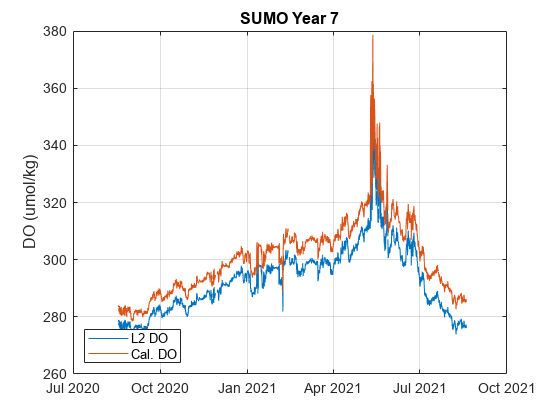

% Remove biofouling 
figure
plot(nsif_DO7.DOdt,nsif_DO7.DOcorr_umolkg,'.')
hold on
plot(buoy_DO7.DOdt,buoy_DO7.DOcorr_umolkg,'k')
ylabel('Calibrated DO (umol/kg)')


% Visually determined biofouling in NSIF data
bf1 = find(nsif_DO7.DOdt > datetime(2021,07,13));

nsif_DO7.DOqaqc_umolkg = nsif_DO7.DOcorr_umolkg;
nsif_DO7.DOqaqc_umolkg(bf1) = NaN;
buoy_DO7.DOqaqc_umolkg = buoy_DO7.DOcorr_umolkg; % No biofouling signal

figure
plot(nsif_DO7.DOdt,nsif_DO7.DOqaqc_umolkg,'.')
hold on
plot(buoy_DO7.DOdt,buoy_DO7.DOqaqc_umolkg,'k')
ylabel('Calibrated DO (umol/kg)')

% Take mean of sumo/nsif to create mixed layer product 
ML_DO7 = merge_DOassets_TT(nsif_DO7,buoy_DO7,'mean');


## Deployment 8 DO Calibration 

#### Calculate AA gain at beginning of deployment

% [nsif_yr8s, nsif_yr8s_tbl] = AAgain_from_CTDcasts(nsif_DO8,downcasts_yr8,cast_num_yr8,AssetRadius,'NSIF','deployment'); % start
[buoy_yr8s, buoy_yr8s_tbl] = AAgain_from_CTDcasts(buoy_DO8,downcasts_yr8,cast_num_yr8,AssetRadius,'SUMO','deployment'); % start
buoy_yr8s_tbl

#### Calculate AA gain at end of deployment

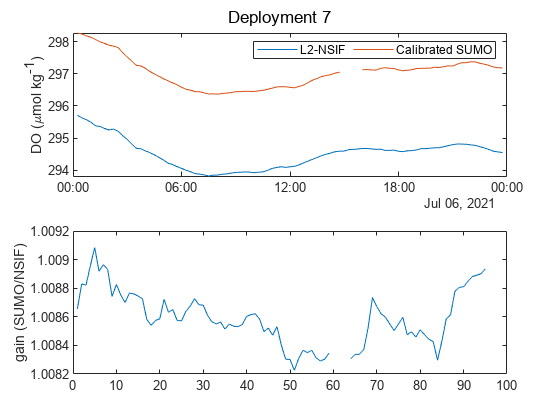

% %% Load in calibrated CTD profiles and bottle files 
% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Processed')
% load Year9_Processed_KF.mat
% [nsif_yr8e, nsif_yr8e_tbl] = AAgain_from_CTDcasts(nsif_DO8,downcasts_yr9,cast_num_yr9,AssetRadius,'NSIF','recovery'); % end
% [buoy_yr8e, buoy_yr8e_tbl] = AAgain_from_CTDcasts(buoy_DO8,downcasts_yr9,cast_num_yr9,AssetRadius,'SUMO','recovery'); % end
% nsif_yr8e_tbl
% buoy_yr8e_tbl

## Year 8: Make Gain corrections

% Buoy
gain_deploy = buoy_yr8s_tbl.Gain_Start_DOML(buoy_yr8s_tbl.Cast == 5); 

dt_recover = datetime
   06-Jul-2021 12:00:00


dt_deploy = buoy_yr8s_tbl.AA_Time(buoy_yr8s_tbl.Cast == 5);

gain_recover = 1.0086

gain_std = 2.6750e-04

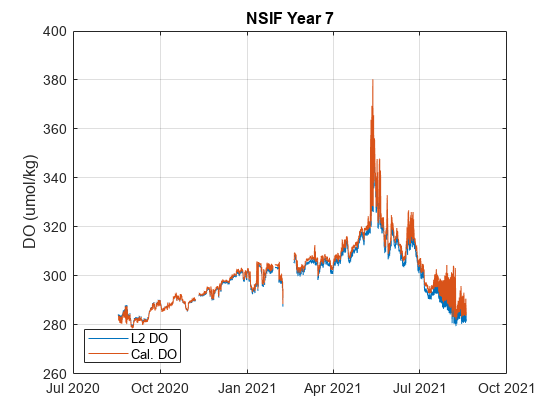

gain_recover = gain_deploy; % Data stopped before recovery casts  

dt_recover = buoy_DO8.DOdt(end); % data stopped before recovery casts 

buoy_DO8 = asset_gain_correction(buoy_DO8,gain_deploy,gain_recover,dt_deploy,dt_recover,'SUMO Year 8');

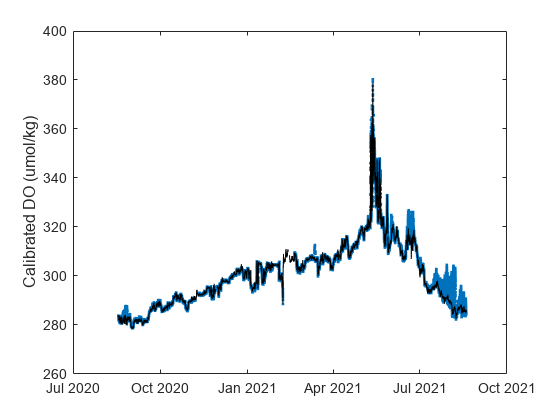


% Find overlap between NSIF beginning and buoy data 
buoy_ind = find(buoy_DO8.DOdt == datetime(2021,08,20,17,30,00)); % time period that buoy and NSIF start trending together 
nsif_ind = find(nsif_DO8.DOdt == datetime(2021,08,20,17,30,00));


ind_len = 24;

figure
plot(buoy_DO8.DOdt(buoy_ind:buoy_ind + ind_len),buoy_DO8.DOcorr_umolkg(buoy_ind:buoy_ind + ind_len))
hold on
plot(nsif_DO8.DOdt(nsif_ind:nsif_ind + ind_len),nsif_DO8.dissolved_oxygen(nsif_ind:nsif_ind + ind_len))
grid on
legend('Calibrated SUMO','L2 NSIF','Location','SW')
title('Pre-NSIF calibration')


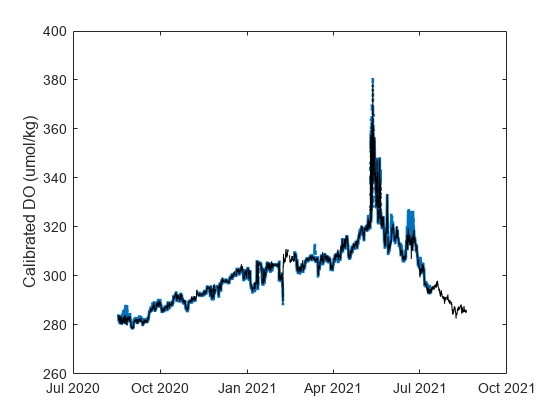

% Calculate gain for NSIF using calibrated SUMO data

gain_mean = nanmean(buoy_DO8.DOcorr_umolkg(buoy_ind:buoy_ind + ind_len)./nsif_DO8.dissolved_oxygen(nsif_ind:nsif_ind + ind_len))

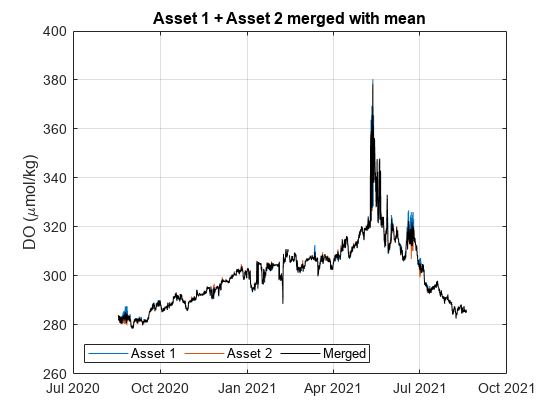

gain_std = nanstd(buoy_DO8.DOcorr_umolkg(buoy_ind:buoy_ind + ind_len)./nsif_DO8.dissolved_oxygen(nsif_ind:nsif_ind + ind_len))

%NSIF

calcasts =      5
     6


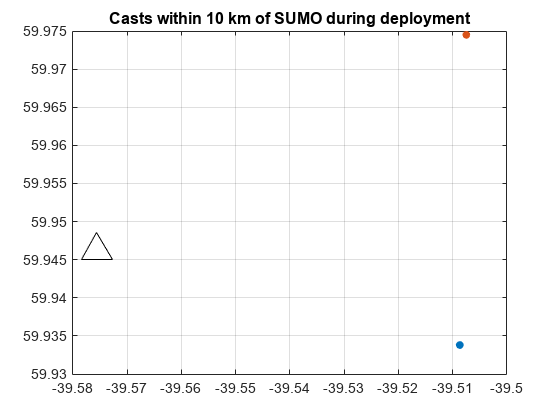

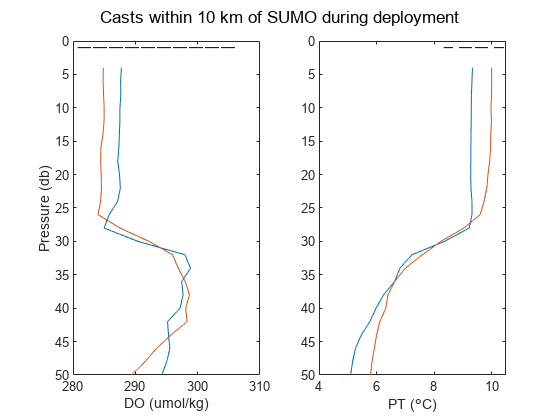

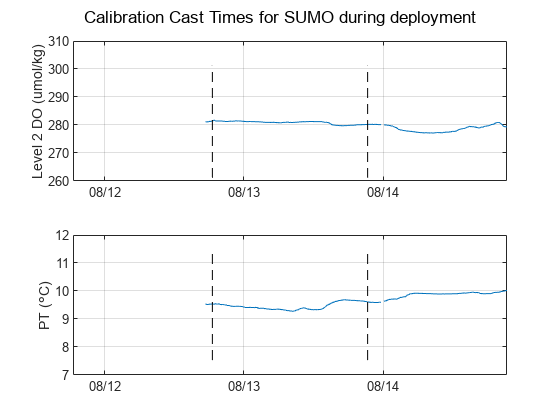

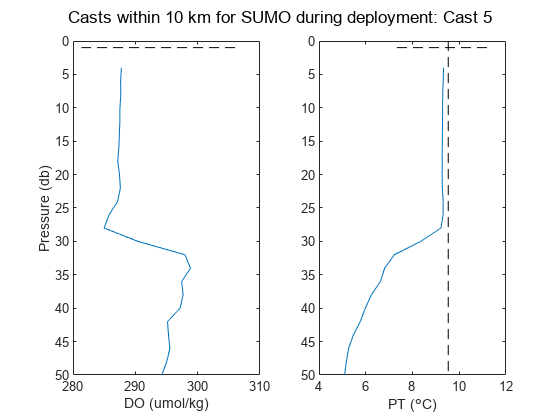

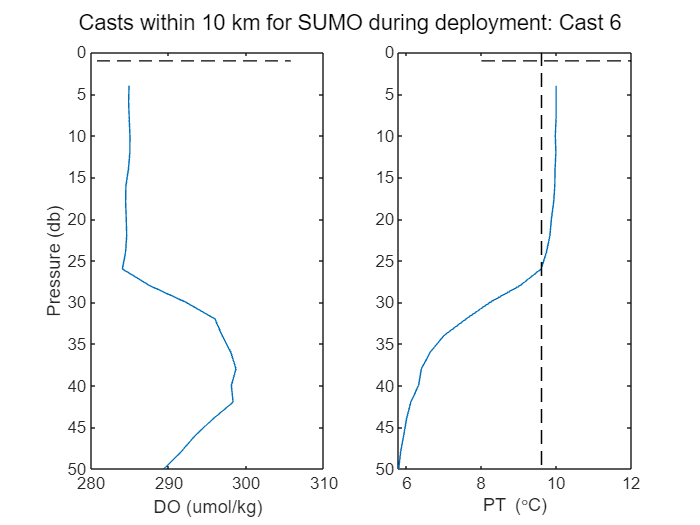

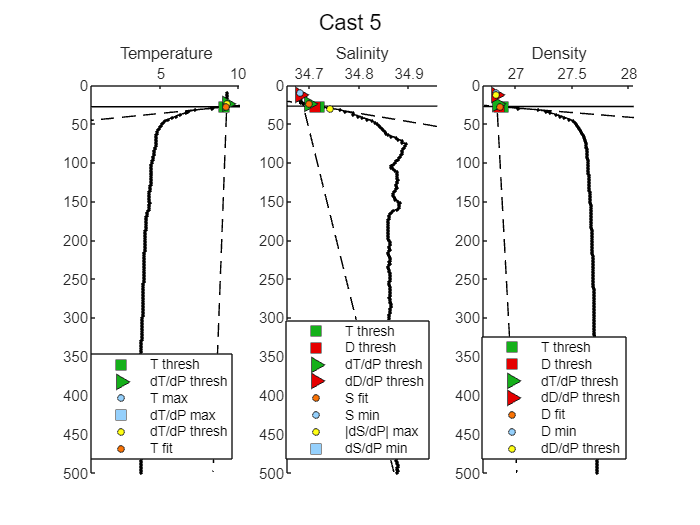

buoy_yr8s_tbl = 2×24 table
    Asset       cal_type      Cast          CastTime                AA_Time           AA_prs    AA_pt     AA_DO_umolkg    Cast_prs    Cast_pt_prs    Cast_DO_umolkg_prs    Gain_Start_prs    mld_prs    Cast_ML_mean_pt    Cast_ML_std_pt    Cast_ML_mean_DO    Cast_ML_std_DO    Gain_Start_ML    DOmld_prs    Cast_DOML_mean_pt    Cast_DOML_std_pt    Cast_DOML_mean_DO    Cast_DOML_std_DO    Gain_Start_DOML
    ______    ____________    ____    ____________________    ____________________

gain_deploy = gain_mean; % No overlap between asset start and calibration casts 
gain_recover = gain_mean; % Data stopped before recovery casts   
 
dt_deploy = nsif_DO8.DOdt(1);
dt_recover = nsif_DO8.DOdt(end); % Data stopped before recovery casts 
nsif_DO8 = asset_gain_correction(nsif_DO8,gain_deploy,gain_recover,dt_deploy,dt_recover,'NSIF Year 8');

figure
plot(buoy_DO8.DOdt(buoy_ind:buoy_ind + ind_len),buoy_DO8.DOcorr_umolkg(buoy_ind:buoy_ind + ind_len))
hold on
plot(nsif_DO8.DOdt(nsif_ind:nsif_ind + ind_len),nsif_DO8.DOcorr_umolkg(nsif_ind:nsif_ind + ind_len))
grid on
legend('Calibrated SUMO','Calibrated NSIF','Location','SW')
title('NSIF Calibrated with SUMO')

% Take mean of sumo/nsif to create mixed layer product 
buoy_DO8.DOqaqc_umolkg = buoy_DO8.DOcorr_umolkg; % No biofouling signal
nsif_DO8.DOqaqc_umolkg = nsif_DO8.DOcorr_umolkg; % No biofouling signal
ML_DO8 = merge_DOassets_TT(nsif_DO8,buoy_DO8,'mean');

- Deployment: Casts end on 17-Aug-2021 and NSIF starts 19-Aug-2021 

- No overlap between turn-around cruise and asset for starting calibration 

- *** Should be able to calibrate NSIF with time series from surface mooring @ 1 m

- Recovery: Asset failed before recovery turnaround cruise, no recovery calibration

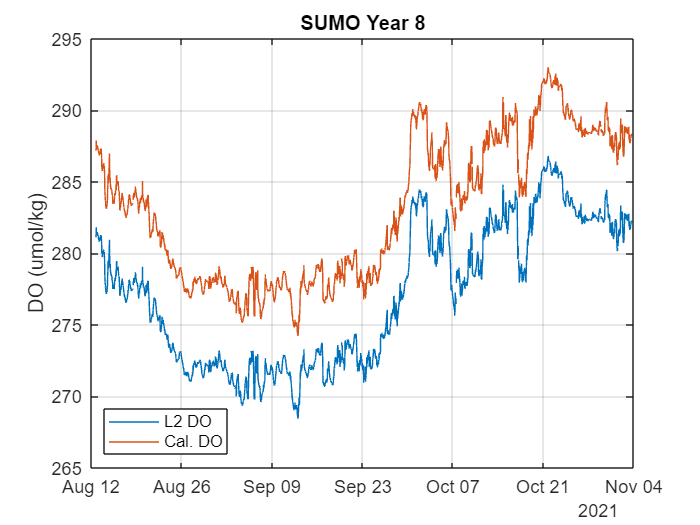


ML_DO = merge_DOassets_TT(ML_DO5,ML_DO6,'mean');
ML_DO = merge_DOassets_TT(ML_DO,ML_DO7,'mean');
ML_DO = merge_DOassets_TT(ML_DO,ML_DO8,'mean');

## Final Calibrated Mixed Layer Dissolved Oxygen Product 

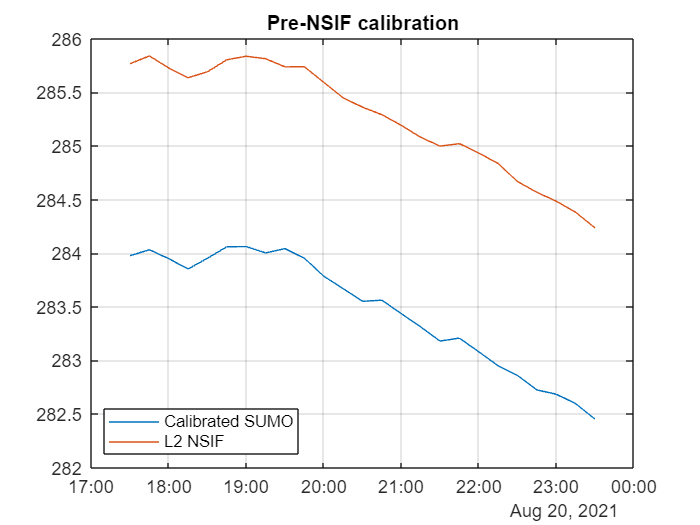

figure
plot(ML_DO.DOdt,ML_DO.DO_umolkg_final,'k')
ylabel('DO (\mumol/kg)')
title('Mixed Layer Dissolved Oxygen')
grid on
axis tight

figure
plot(ML_DO.DOdt,ML_DO.t,'k')
ylabel('Temp (\circC)')
title('Mixed Layer Temperature')
grid on

axis tight

figure
plot(ML_DO.DOdt,ML_DO.SP,'k')
ylabel('Salinity')

gain_mean = 0.9937

title('Mixed Layer Salinity')

gain_std = 1.4611e-04

grid on
axis tight

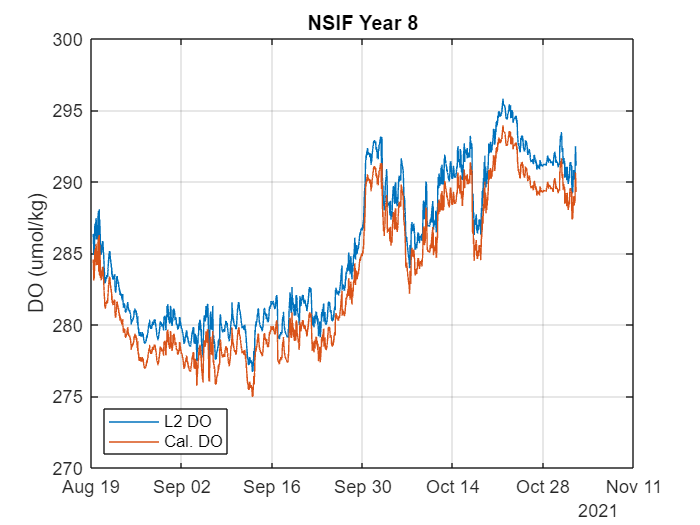

function deployment = pull_DO_Data_from_THREDDS(deploy_num,asset)
%   deploy_num = 'deployment0012' % string of deployment you want 
options = weboptions('Timeout', 600);

% asset = 'GI03FLMA-RIS01-03-DOSTAD000-recovered_host-dosta_abcdjm_sio_instrument_recovered'; % APEX NSIF
base_catalog_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/';

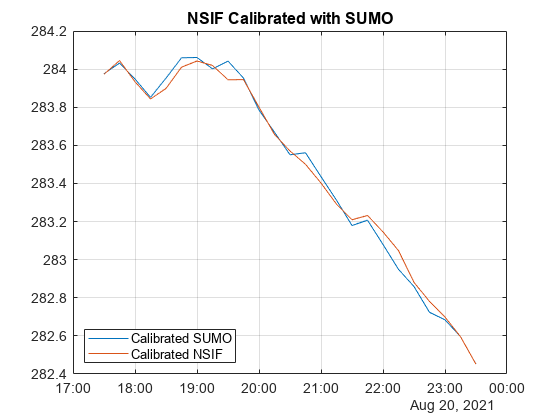


catalog = webread(strcat(base_catalog_url,asset,'/catalog.html'),options);
nclist = regexp(catalog,'<a href=''([^>]+.nc)''>','tokens');
base_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/dodsC/';

% Find DOSTA files (excludes FLORT and CTD files 
[~, DOSTAind] = find(contains(string(nclist),deploy_num) == 1 & ~contains(string(nclist),'CTD') & ~contains(string(nclist),'flort')...
    & ~contains(string(nclist),'METBK'));

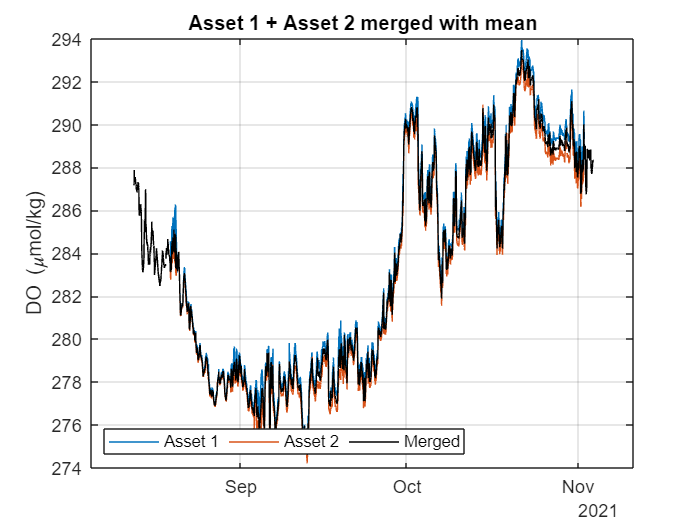


bigfile = [];
    for i = 1:length(DOSTAind)
           
        DOSTA_url_thredds = nclist{1,DOSTAind(i)}{1,1}; 

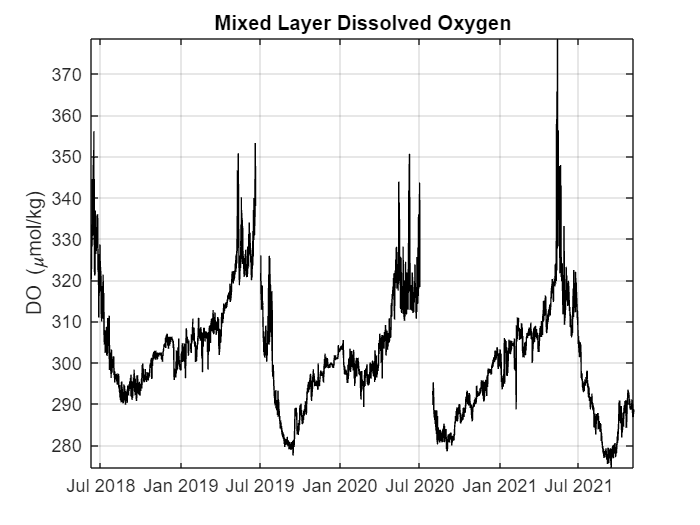

        DOSTA_url_thredds = strcat(base_url,DOSTA_url_thredds(22:end),'#fillmismatch');
        ncdisp(DOSTA_url_thredds) % Displays all info for variables in netCDF
        vinfo = ncinfo(DOSTA_url_thredds);
%         disp(['file number = ' num2str(i)])
%         disp({vinfo.Variables.Name}')
%         ncreadatt(DOSTA_url_thredds,'sea_water_practical_salinity','instrument')

        VarCheck = max(strncmpi({vinfo.Variables.Name},'dissolved_oxygen',1));
    
            if VarCheck == 1
            
                % time
                time = ncread(DOSTA_url_thredds,'time');

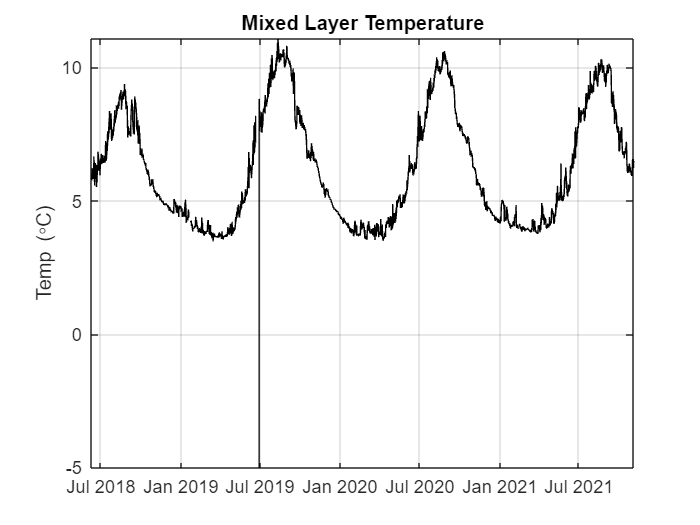

                DOdn = datenum(1900,1,1,0,0,0)+(time/60/60/24);
%                 file{i}.DOdt = datetime(DOdn,'ConvertFrom','datenum','TimeZone','UTC');
                file{i}.DOdt = datetime(DOdn,'ConvertFrom','datenum');
                file{i}.DOdn = DOdn;
                
                % deployment/lat/lon
                file{i}.deployment = ncread(DOSTA_url_thredds,'deployment');

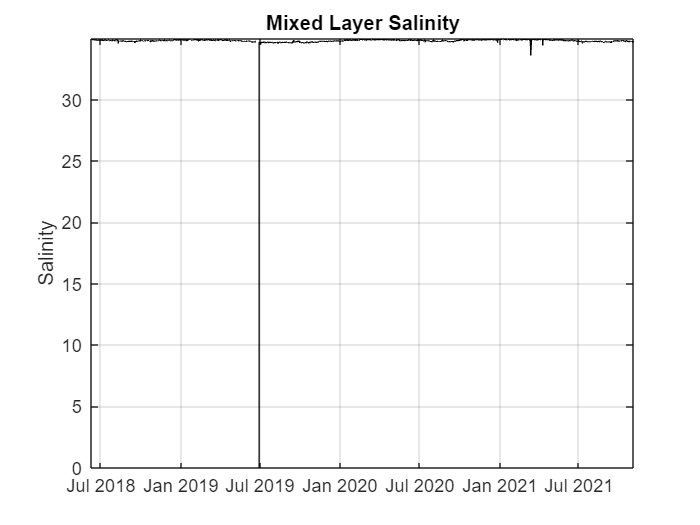

                lat = ncreadatt(DOSTA_url_thredds,'/','lat');
                lon = ncreadatt(DOSTA_url_thredds,'/','lon');
                file{i}.lat = ones(length(time),1)*lat;  
                file{i}.lon = ones(length(time),1)*lon; 
                SN = str2num(ncreadatt(DOSTA_url_thredds,'/','SerialNumber'));
                file{i}.serial_number = ones(length(time),1)*SN; clear DOdn lat lon SN
                

                % Oxygen
                file{i}.dissolved_oxygen = ncread(DOSTA_url_thredds,'dissolved_oxygen');
                file{i}.dissolved_oxygen_qc_executed = ncread(DOSTA_url_thredds,'dissolved_oxygen_qc_executed');
                file{i}.dissolved_oxygen_qc_results = ncread(DOSTA_url_thredds,'dissolved_oxygen_qc_results');
                file{i}.calibrated_phase = ncread(DOSTA_url_thredds,'calibrated_phase');

                % Ancillary 
                file{i}.optode_temperature = ncread(DOSTA_url_thredds,'optode_temperature');
                    try
                        file{i}.sea_water_temperature = ncread(DOSTA_url_thredds,'sea_water_temperature');
                    catch
                        warning('no variable called sea_water_temperature, using sea_surface_temperature variable')
                        file{i}.sea_water_temperature = ncread(DOSTA_url_thredds,'sea_surface_temperature');
                    end
                    try 
                        file{i}.sea_water_practical_salinity = ncread(DOSTA_url_thredds,'sea_water_practical_salinity');
                    catch
                        warning('no variable called sea_water_practical_salinity, using met_salsurf variable')
                        file{i}.sea_water_practical_salinity = ncread(DOSTA_url_thredds,'met_salsurf');
                    end                
                file{i}.estimated_oxygen_concentration = ncread(DOSTA_url_thredds,'estimated_oxygen_concentration');
                file{i}.estimated_oxygen_concentration_qc_executed = ncread(DOSTA_url_thredds,'estimated_oxygen_concentration_qc_executed');
                file{i}.estimated_oxygen_concentration_qc_results = ncread(DOSTA_url_thredds,'estimated_oxygen_concentration_qc_results');
                    try
                        file{i}.prs = ncread(DOSTA_url_thredds,'int_ctd_pressure'); % dbar 
                    catch
                        warning('no variable called int_ctd_pressure, setting pressure as 1 db')
                        file{i}.prs = ones(length(time),1); clear time 
                    end
                % Concatenate files into one big table 
                bigfile = [bigfile; struct2table(file{i})];
%                 bigfile.Properties.Description = asset; 
            end

        if VarCheck ~=1
            disp('No DO data')
        end

    end
deployment = bigfile; 
end

function asset_name = GSW_variables(asset_name)

    % Calculate other parameters of interest
    asset_name.t = asset_name.sea_water_temperature;
    asset_name.SP = asset_name.sea_water_practical_salinity; 
    asset_name.SA = gsw_SA_from_SP(asset_name.SP,asset_name.prs,asset_name.lon,asset_name.lat);
    asset_name.CT = gsw_CT_from_t(asset_name.SA,asset_name.t,asset_name.prs);
    asset_name.pt = gsw_pt_from_CT(asset_name.SA,asset_name.CT);  
    asset_name.O2sol_umolkg = gsw_O2sol(asset_name.SA,asset_name.CT,asset_name.prs,asset_name.lon,asset_name.lat);
    asset_name.rho = gsw_rho_CT_exact(asset_name.SA,asset_name.CT,asset_name.prs); % in situ density
    asset_name.prho = gsw_rho_CT_exact(asset_name.SA,asset_name.CT,0); % potential density with ref == surf
    asset_name.sigma0 = gsw_sigma0_CT_exact(asset_name.SA,asset_name.CT); % cast.prho - 1000 = cast.sigma0 

end

function TT = burst_THREDDS_files_to_timetable(table_in,retime_dt)
% table_in = table;
% retime_dt = minutes(15); 

TT0 = table_in;
TT0 = table2timetable(TT0);
TT0 = sortrows(TT0); % sort by time

uniqueRowsTT = unique(TT0); %unique times

% Find duplicate times and average them 
dupTimes = sort(uniqueRowsTT.DOdt);
tf = (diff(dupTimes) == 0);
dupTimes = dupTimes(tf);
dupTimes = unique(dupTimes);
uniqueTimes = unique(uniqueRowsTT.DOdt);

    if ~isempty(dupTimes)
    %      TT = retime(uniqueRowsTT,uniqueTimes,'mean'); % If want mean 
        TT = retime(uniqueRowsTT,uniqueTimes,'firstvalue'); % If want first value 
        % lastUniqueRowsTT = retime(uniq'ueRowsTT,uniqueTimes,'lastvalue') % If want last value 
    else
        TT = uniqueRowsTT;
    end

TT = retime(TT,'regular','median','TimeStep',retime_dt);
end


function [caltable, calcast_tbl] = AAgain_from_CTDcasts(asset,casts,cast_num,AssetRadius,asset_name,cal_type)
    % Example:
    % asset = nsif_DO5;
    % cast_num = cast_num_yr5;
    % casts = downcasts_yr5; 
    % AssetRadius = 10; % in km 
    % asset_name = 'NSIF';
    % cal_type = 'deploy'; % or 'recover'
    
    addpath(genpath('G:\My Drive\Matlab_work\Github\OOI_Irminger_students\common'))
    AssetStart = asset.DOdt(1); 
    ind = [];
    for i = 1:length(cast_num)
        d = distlatlon(asset.lat(1),casts{cast_num(i)}.lat(1),asset.lon(1),casts{cast_num(i)}.lon(1));
        CastStart = casts{cast_num(i)}.StartTimeUTC;
        if d < AssetRadius & CastStart > AssetStart 
            ind(i) = 1;
        else ind(i) = 0;
        end
    end
    
    calcasts = cast_num(ind == 1)
    
    figure % shows locations of CTD profiles 
    for i = 1:length(calcasts)
        plot(casts{calcasts(i)}.lon(1),casts{calcasts(i)}.lat(1),'.','Markersize',20)
        hold on
    end
    grid on
    plot(asset.lon(1),asset.lat(1),'^k','MarkerSize',20)
    title(['Casts within ' num2str(AssetRadius) ' km of ' asset_name ' during ' cal_type])

    if isempty(calcasts)
        disp('No Cal Cast/Asset overlap in space and time')
        caltable = [];
        calcast_tbl = [];
    end
        
    if ~isempty(calcasts)
        figure % shows top 50 m of all casts within Asset radius
        for i = 1:length(calcasts)

            subplot(1,2,1)
            plot(casts{calcasts(i)}.DOcorr_umolkg,casts{calcasts(i)}.prs)
            hold on
            axis ij
            ylim([0 50])
            l = line([max(casts{calcasts(i)}.DOcorr_umolkg)-20 max(casts{calcasts(i)}.DOcorr_umolkg)+5],[nanmean(asset.prs) nanmean(asset.prs)]);
            l.Color = 'k'; l.LineStyle = '--';
            ylabel('Pressure (db)'); xlabel('DO (umol/kg)')
        
            subplot(1,2,2)
            plot(casts{calcasts(i)}.pt,casts{calcasts(i)}.prs)
            hold on
            axis ij
            ylim([0 50])
            l = line([max(casts{calcasts(i)}.pt)-1 max(casts{calcasts(i)}.pt)+0.5],[nanmean(asset.prs) nanmean(asset.prs)]);
            l.Color = 'k'; l.LineStyle = '--';
            xlabel('PT (\circC)')
            sgtitle(['Casts within ' num2str(AssetRadius) ' km of ' asset_name ' during ' cal_type])
        end

        
        
        figure % shows when casts occurred during asset time series 
        subplot(2,1,1)
        plot(asset.DOdn,asset.dissolved_oxygen)
            for i = 1:length(calcasts)
                l = line([datenum(casts{calcasts(i)}.StartTimeUTC(1)) datenum(casts{calcasts(i)}.StartTimeUTC(1))],[asset.dissolved_oxygen(1)-20 asset.dissolved_oxygen(1)+20]);
                l.Color = 'k'; l.LineStyle = '--';
            end
        xlim([datenum(casts{calcasts(1)}.StartTimeUTC(1))-1 datenum(casts{calcasts(end)}.StartTimeUTC(1) + 1 )])
        datetick('x','keeplimits')
        grid on
        ylabel('Level 2 DO (umol/kg)')
        
        subplot(2,1,2)
        plot(asset.DOdn,asset.pt)
            for i = 1:length(calcasts)
                l = line([datenum(casts{calcasts(i)}.StartTimeUTC(1)) datenum(casts{calcasts(i)}.StartTimeUTC(1))],[asset.pt(1)-2 asset.pt(1)+2]);
                l.Color = 'k'; l.LineStyle = '--';
            end
        xlim([datenum(casts{calcasts(1)}.StartTimeUTC(1))-1 datenum(casts{calcasts(end)}.StartTimeUTC(1) + 1 )])
        datetick('x','keeplimits')
        ylabel('PT (\circC)')
        grid on
        sgtitle(['Calibration Cast Times for ' asset_name ' during ' cal_type])
        
        casttable = [];
        for i = 1:length(calcasts)
            if asset.DOdt(end) > casts{calcasts(i)}.StartTimeUTC(1)
                [~,ind] = min(abs(casts{calcasts(i)}.StartTimeUTC(1) - asset.DOdt)); % find where cast time and asset time are closest 
                casttable{calcasts(i)} = table(string(asset_name), string(cal_type), calcasts(i), casts{calcasts(i)}.StartTimeUTC(1), asset.DOdt(ind), asset.prs(ind), asset.pt(ind), asset.dissolved_oxygen(ind),...
                'VariableNames',{'Asset','cal_type','Cast','CastTime', 'AA_Time','AA_prs','AA_pt','AA_DO_umolkg'});
            elseif asset.DOdt(end) < casts{calcasts(i)}.StartTimeUTC(1)
                casttable{calcasts(i)} = table(string(asset_name), string(cal_type), calcasts(i), casts{calcasts(i)}.StartTimeUTC(1), NaT, NaN, NaN, NaN,...
                'VariableNames',{'Asset','cal_type','Cast','CastTime', 'AA_Time','AA_prs','AA_pt','AA_DO_umolkg'});
            end
        end
        
        for i = 1:length(calcasts)
            figure % shows where asset prs and PT overlap with turn-around cruise cast 
            subplot(1,2,1)
            plot(casts{calcasts(i)}.DOcorr_umolkg,casts{calcasts(i)}.prs)
            hold on
            axis ij
            ylim([0 50])
            l = line([max(casts{calcasts(i)}.DOcorr_umolkg)-20 max(casts{calcasts(i)}.DOcorr_umolkg)+5],[casttable{calcasts(i)}.AA_prs casttable{calcasts(i)}.AA_prs]);
            l.Color = 'k'; l.LineStyle = '--';
            ylabel('Pressure (db)'); xlabel('DO (umol/kg)')
        
            subplot(1,2,2)
            plot(casts{calcasts(i)}.pt,casts{calcasts(i)}.prs)
            hold on
            axis ij
            ylim([0 50])
            l = line([max(casts{calcasts(i)}.pt)-2 max(casts{calcasts(i)}.pt)+2],[casttable{calcasts(i)}.AA_prs casttable{calcasts(i)}.AA_prs]);
            l.Color = 'k'; l.LineStyle = '--';
            l2 = line([casttable{calcasts(i)}.AA_pt casttable{calcasts(i)}.AA_pt],[0 50]);
            l2.Color = 'k'; l2.LineStyle = '--';
            xlabel('PT (\circC)')
            sgtitle(['Casts within ' num2str(AssetRadius) ' km for ' asset_name ' during ' cal_type ': Cast ' num2str(calcasts(i))])
        end

       
        addpath(genpath('G:\My Drive\Matlab_work\Github\CDT\cdt'))
        % Calculate mixed layer depths to look at oxygen variability in ML
        pmld = []; mldtbl = []; DOmld = [];
        for i = 1:length(calcasts)
            [pmld{calcasts(i)},mldtbl{calcasts(i)}] = mld(casts{calcasts(i)}.prs,casts{calcasts(i)}.t,casts{calcasts(i)}.SP,'metric','hybrid','plot','true');
            [DOmld{calcasts(i)}] = mld(casts{calcasts(i)}.prs,casts{calcasts(i)}.DOcorr_umolkg,'metric','threshold','tthresh',1);
            sgtitle(['Cast ' num2str(calcasts(i))])
        end
        
        for i = 1:length(calcasts)
            % Based on pressure matching between cast and OOI AA asset 
            [~,b] = min(abs(casts{calcasts(i)}.prs - casttable{calcasts(i)}.AA_prs)); % finds cast pressure closest to NSIF AA pressure
            if mode(asset.prs) == 1
                [~,b] = min(casts{calcasts(i)}.prs); % Finds shallowest CTD point to compare to buoy depth (1 m)
            end
            casttable{calcasts(i)}.Cast_prs = casts{calcasts(i)}.prs(b); % Records cast pressure closest to NSIF AA pressure 
            casttable{calcasts(i)}.Cast_pt_prs = casts{calcasts(i)}.pt(b);       
            casttable{calcasts(i)}.Cast_DO_umolkg_prs = casts{calcasts(i)}.DOcorr_umolkg(b); % Records cast DO closest to NSIF AA pressure 
            casttable{calcasts(i)}.Gain_Start_prs = casttable{calcasts(i)}.Cast_DO_umolkg_prs/casttable{calcasts(i)}.AA_DO_umolkg; % Calculates gain based on pressure 
            
            % Based on mean mixed-layer concentration  
            casttable{calcasts(i)}.mld_prs = pmld{calcasts(i)}(1); % pulls out MLD calculated for temperature in cell above
            [~,b] = min(abs(casts{calcasts(i)}.prs - pmld{calcasts(i)}(1)));
            casttable{calcasts(i)}.Cast_ML_mean_pt = nanmean(casts{calcasts(i)}.pt(1:b));
            casttable{calcasts(i)}.Cast_ML_std_pt = nanstd(casts{calcasts(i)}.pt(1:b));
            casttable{calcasts(i)}.Cast_ML_mean_DO = nanmean(casts{calcasts(i)}.DOcorr_umolkg(1:b));
            casttable{calcasts(i)}.Cast_ML_std_DO = nanstd(casts{calcasts(i)}.DOcorr_umolkg(1:b));
            casttable{calcasts(i)}.Gain_Start_ML = casttable{calcasts(i)}.Cast_ML_mean_DO/casttable{calcasts(i)}.AA_DO_umolkg;
            % Based on DO mixed layer depth 
            casttable{calcasts(i)}.DOmld_prs = DOmld{calcasts(i)}; % pulls out MLD calculated for temperature in cell above
            [~,b] = min(abs(casts{calcasts(i)}.prs - DOmld{calcasts(i)}));
            casttable{calcasts(i)}.Cast_DOML_mean_pt = nanmean(casts{calcasts(i)}.pt(1:b));
            casttable{calcasts(i)}.Cast_DOML_std_pt = nanstd(casts{calcasts(i)}.pt(1:b));
            casttable{calcasts(i)}.Cast_DOML_mean_DO = nanmean(casts{calcasts(i)}.DOcorr_umolkg(1:b));
            casttable{calcasts(i)}.Cast_DOML_std_DO = nanstd(casts{calcasts(i)}.DOcorr_umolkg(1:b));
            casttable{calcasts(i)}.Gain_Start_DOML = casttable{calcasts(i)}.Cast_DOML_mean_DO/casttable{calcasts(i)}.AA_DO_umolkg;
        end

        caltable = casttable;
    
        calcast_tbl = [];
            for i = 1:length(calcasts)
                data = casttable{calcasts(i)};
                calcast_tbl = [calcast_tbl; data];
            end
    end
end
%%
function asset = asset_gain_correction(asset,gain_deploy,gain_recover,dt_deploy,dt_recover,AssetName)
% example 
% gain_deploy = nsif_yr5s_tbl.Gain_Start_DOML(1); 
% gain_recover = nsif_yr5e_tbl.Gain_Start_DOML(1);
% 
% dt_deploy = nsif_yr5s_tbl.AA_Time(1);
% dt_recover = nsif_yr5e_tbl.AA_Time(1);
% AssetName = 'NSIF Year 5'

gain = [gain_deploy; gain_recover];
dt = [dt_deploy; dt_recover];

asset.gain_ts = interp1(dt,gain,asset.DOdt,'linear','extrap'); % Create timeseries of gain correction 

asset.DOcorr_umolkg = asset.dissolved_oxygen.*asset.gain_ts; 

figure
plot(asset.DOdt,asset.dissolved_oxygen)
hold on
plot(asset.DOdt,asset.DOcorr_umolkg)
ylabel('DO (umol/kg)')
legend('L2 DO', 'Cal. DO','Location','SW')
grid on
title(AssetName)
end

function TT = merge_DOassets_TT(asset1,asset2,retime_type)
%retime_type = 'mean', 'firstvalue','lastvalue')

% Merged product
TT0 = [asset1; asset2];
uniqueRowsTT = unique(TT0); %unique times

% Find duplicate times and average them 
dupTimes = sort(uniqueRowsTT.DOdt);
tf = (diff(dupTimes) == 0);
dupTimes = dupTimes(tf);
dupTimes = unique(dupTimes);
uniqueTimes = unique(uniqueRowsTT.DOdt);

if ~isempty(dupTimes) 
    TT = retime(uniqueRowsTT,uniqueTimes,retime_type); % 'mean','firstvalue','lastvalue'
else
    TT = uniqueRowsTT;
end

if max(contains(TT.Properties.VariableNames,'DO_umolkg_final')) == 0
    TT.DO_umolkg_final = TT.DOqaqc_umolkg; 
    TT.DOdn = datenum(TT.DOdt + mode(diff(TT.DOdt)/2));
    TT.deployment(:) = mode(TT.deployment);
    
    TT = removevars(TT,{'serial_number','dissolved_oxygen','dissolved_oxygen_qc_executed','dissolved_oxygen_qc_results','calibrated_phase',...
        'optode_temperature','estimated_oxygen_concentration','estimated_oxygen_concentration_qc_executed','estimated_oxygen_concentration_qc_results',...
        'gain_ts','DOcorr_umolkg','DOqaqc_umolkg'});
    figure
    plot(asset1.DOdt,asset1.DOqaqc_umolkg)
    hold on
    plot(asset2.DOdt,asset2.DOqaqc_umolkg)
    plot(TT.DOdt,TT.DO_umolkg_final,'k')
    ylabel('DO (\mumol/kg)')
    grid on
    legend('Asset 1','Asset 2','Merged','Orientation','Horizontal','Location','SW')
    title(['Asset 1 + Asset 2 merged with ' retime_type])
end

end
